clear;
clc;

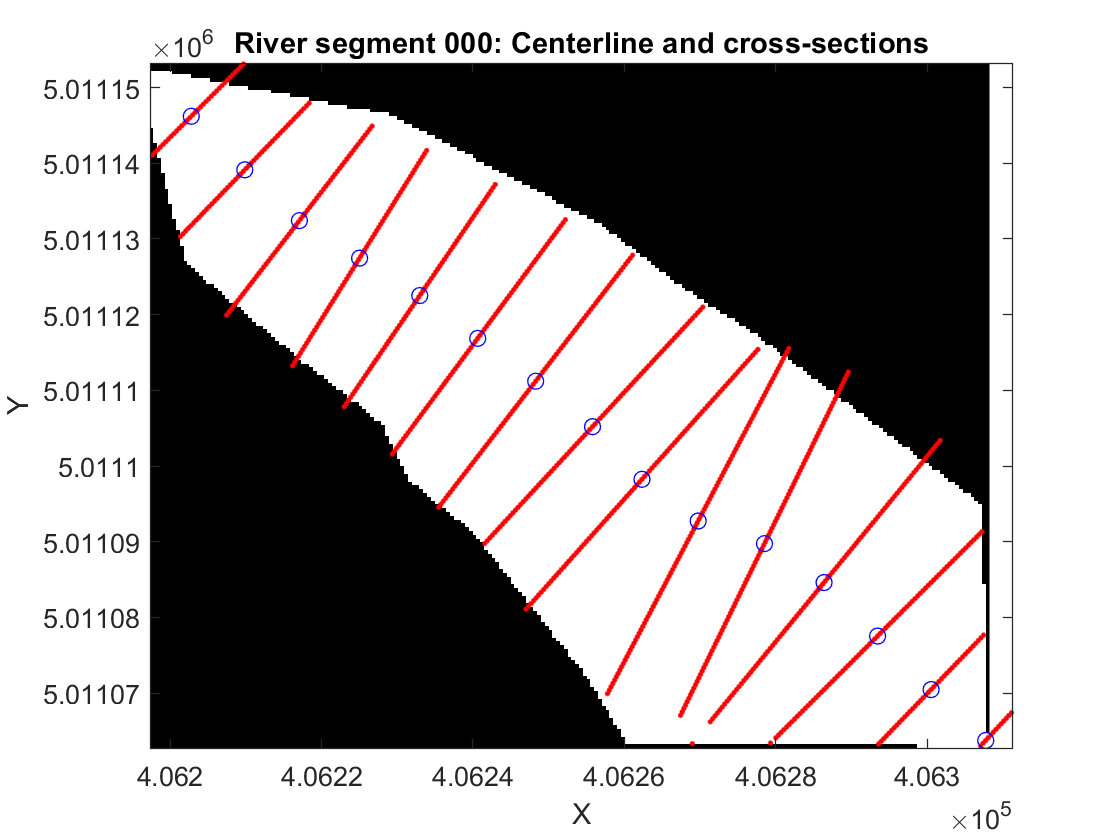

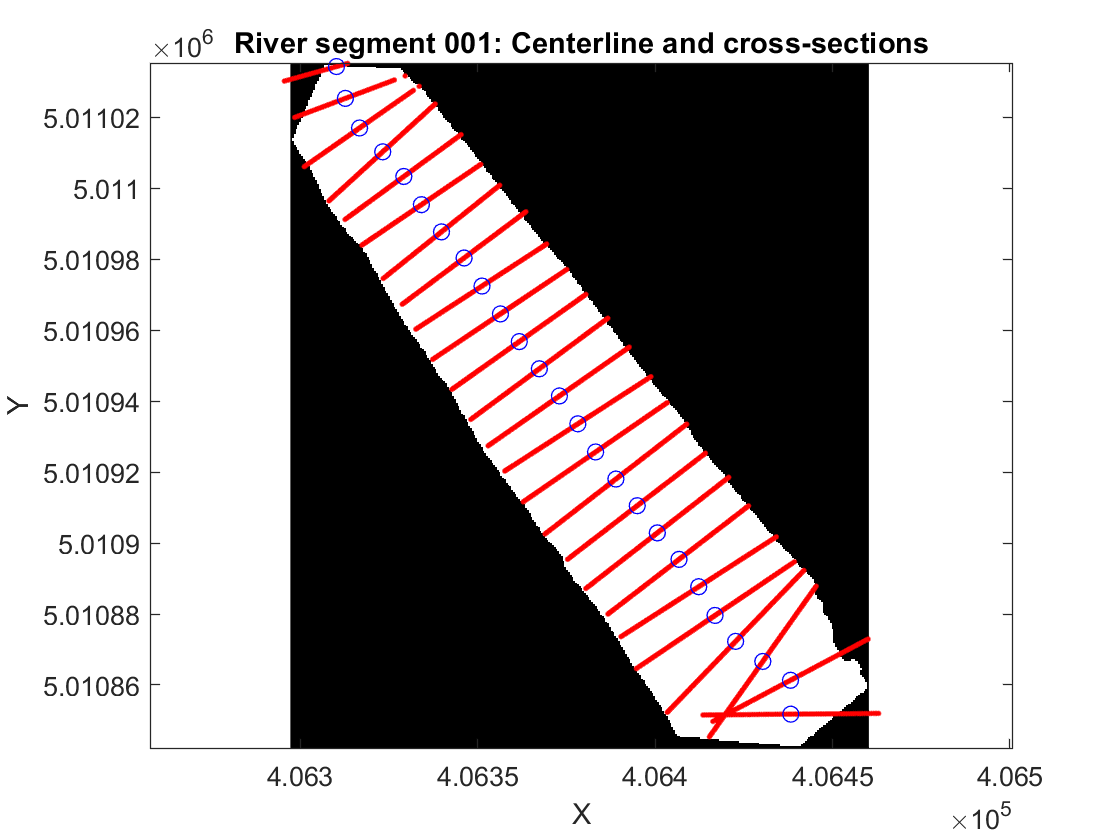

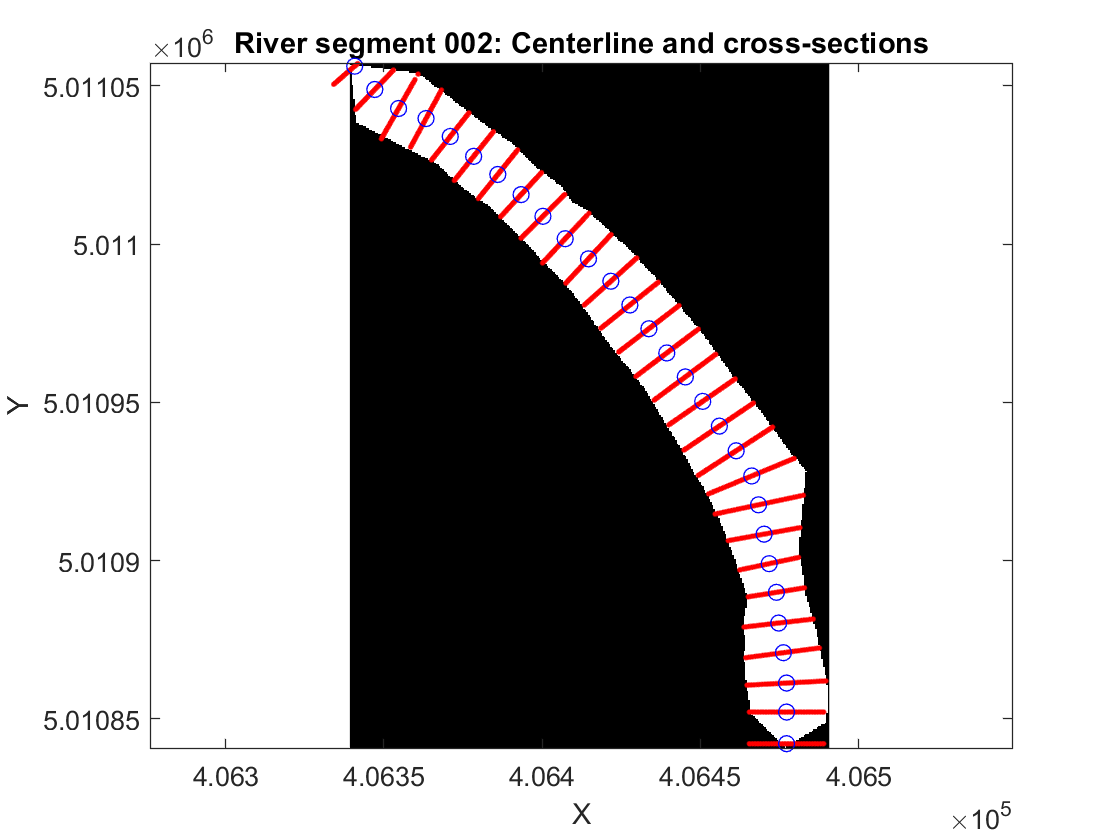

ans = logical
   1


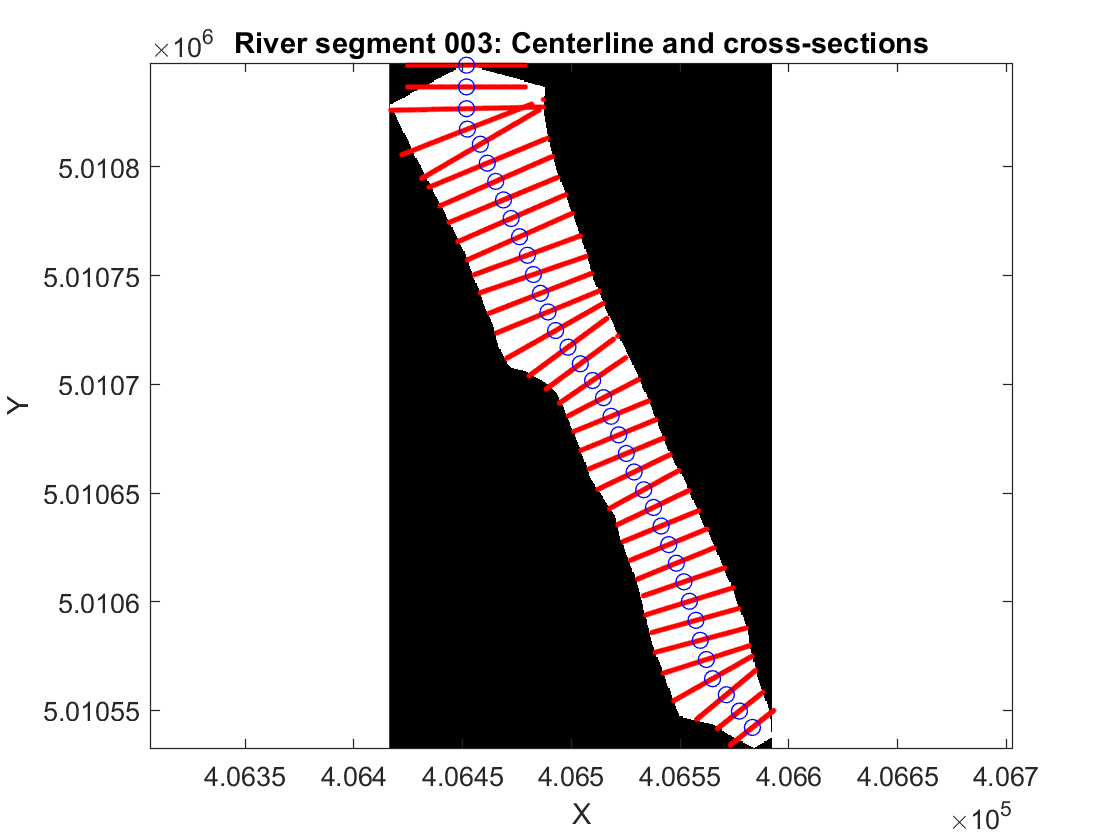

ans = logical
   1


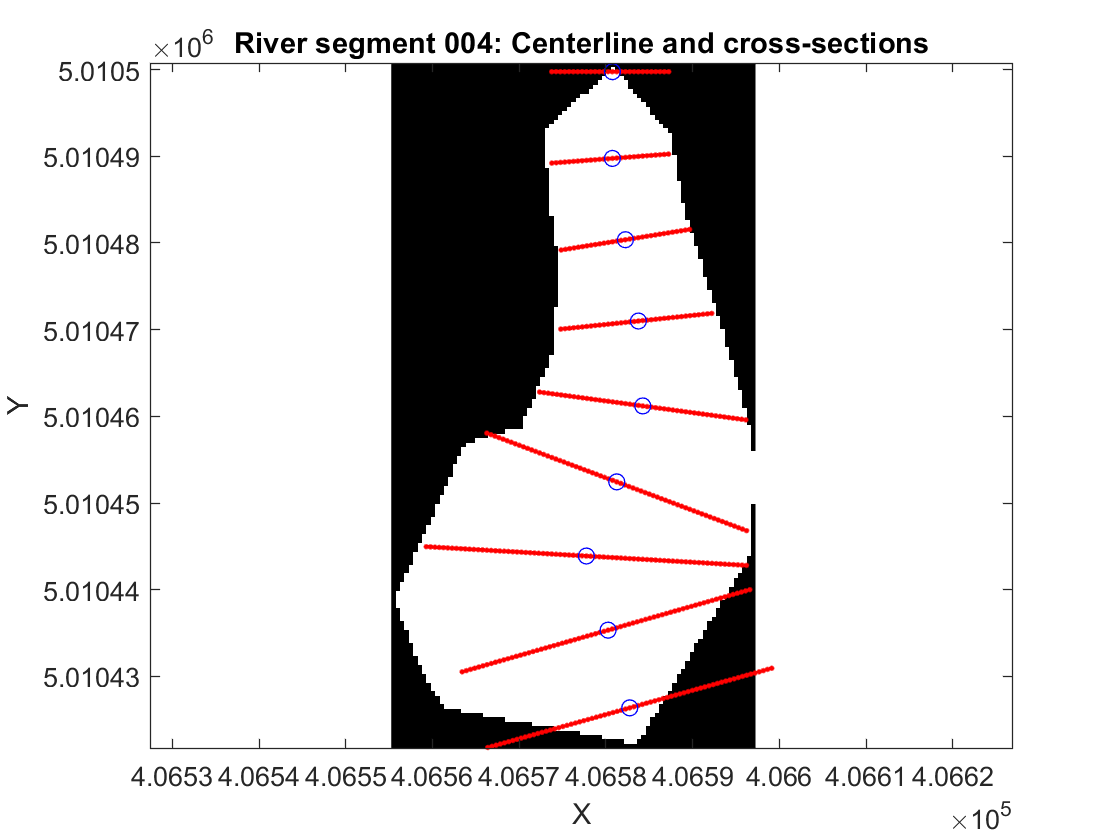

ans = logical
   1


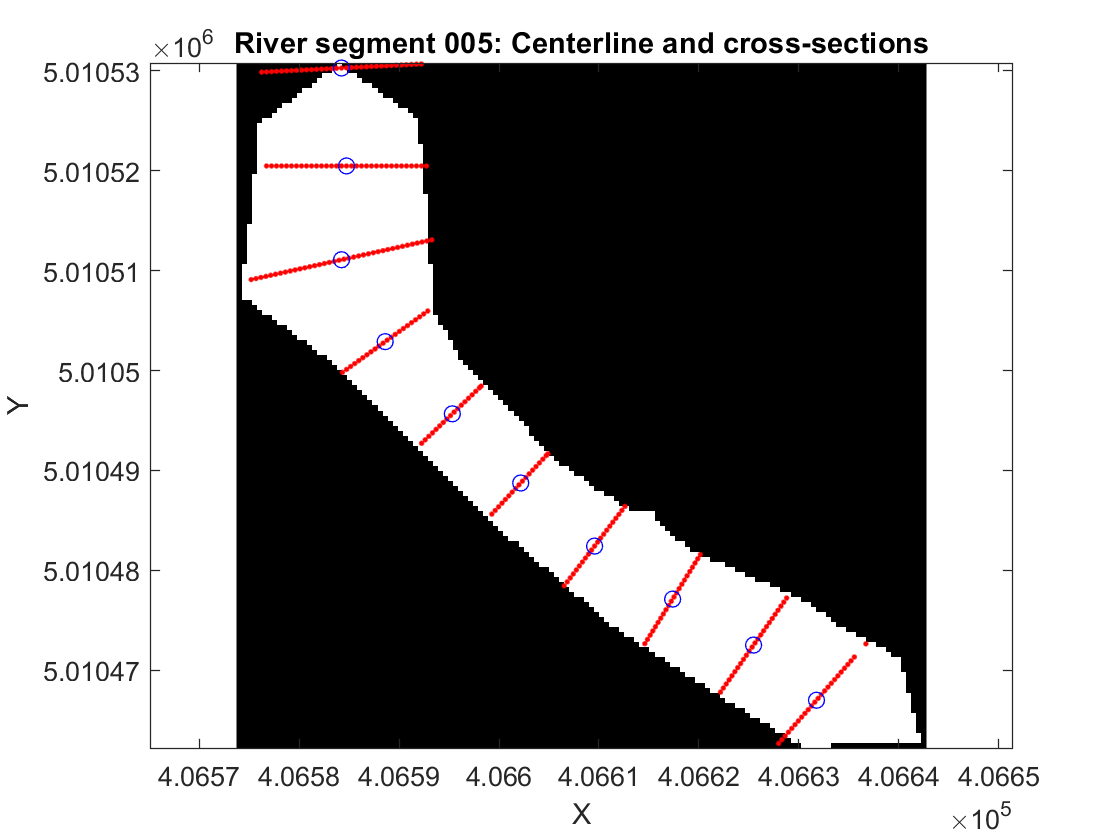

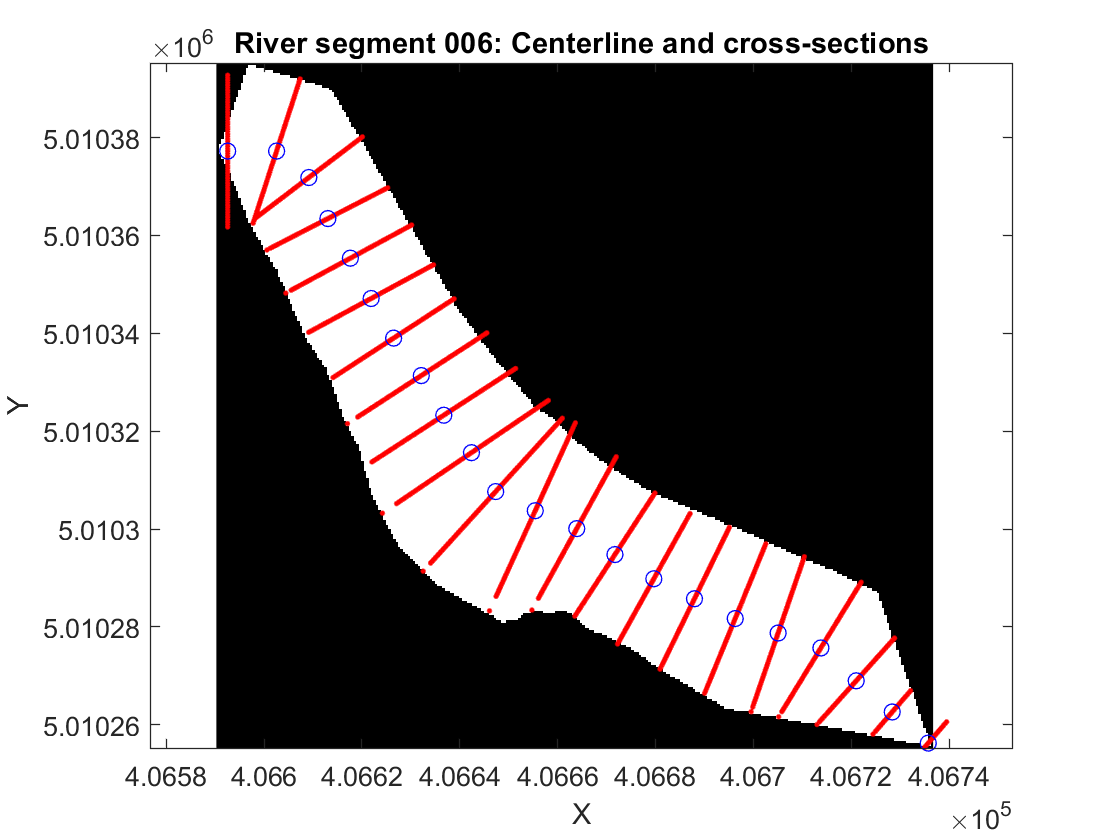

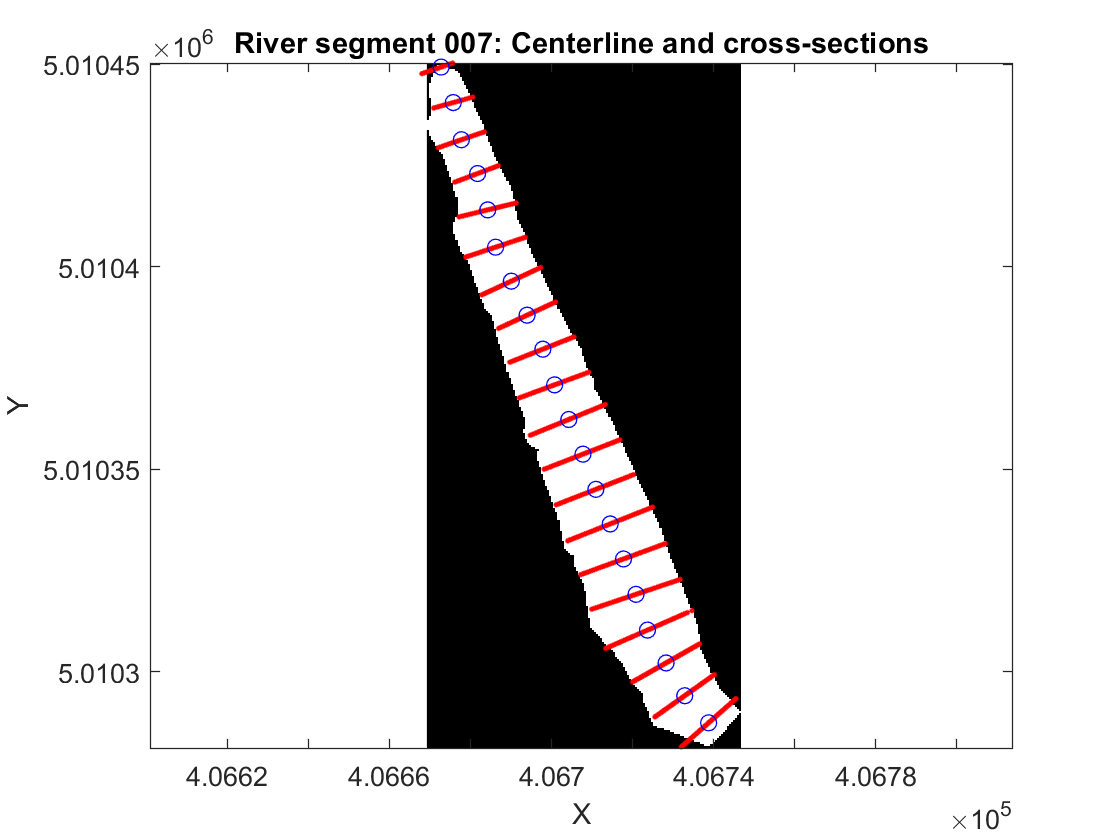

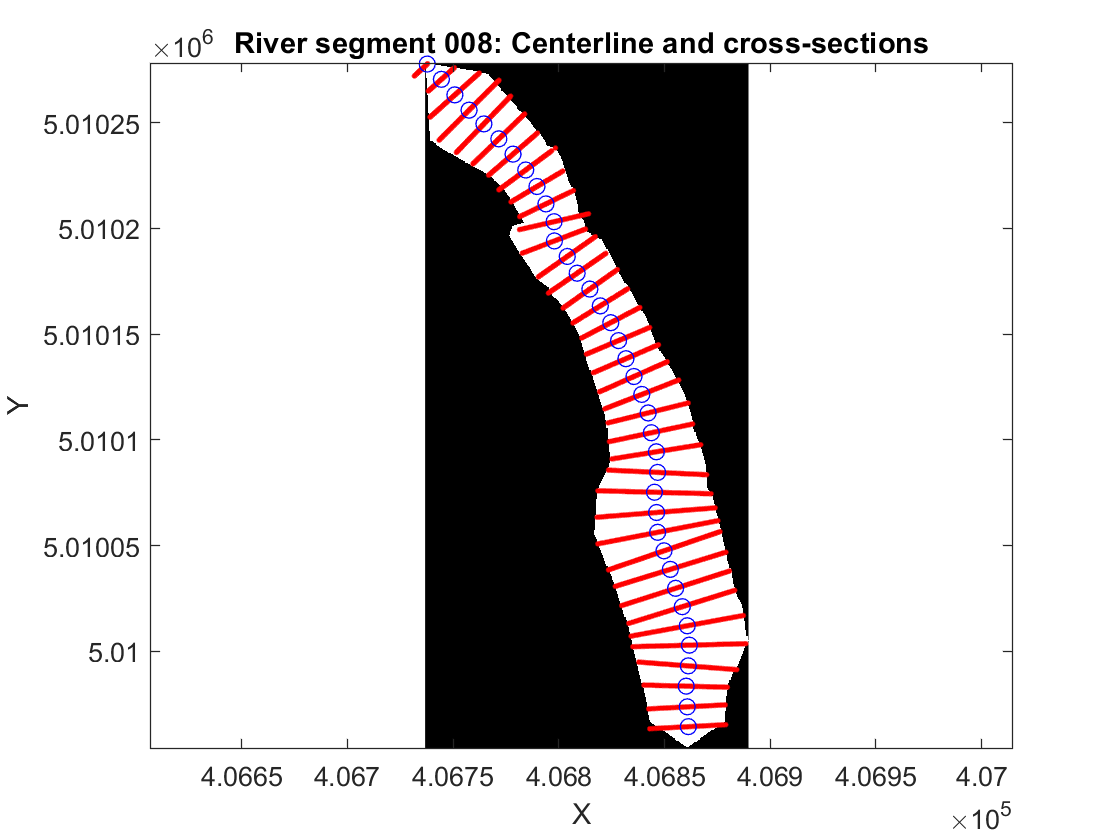

ans = logical
   1


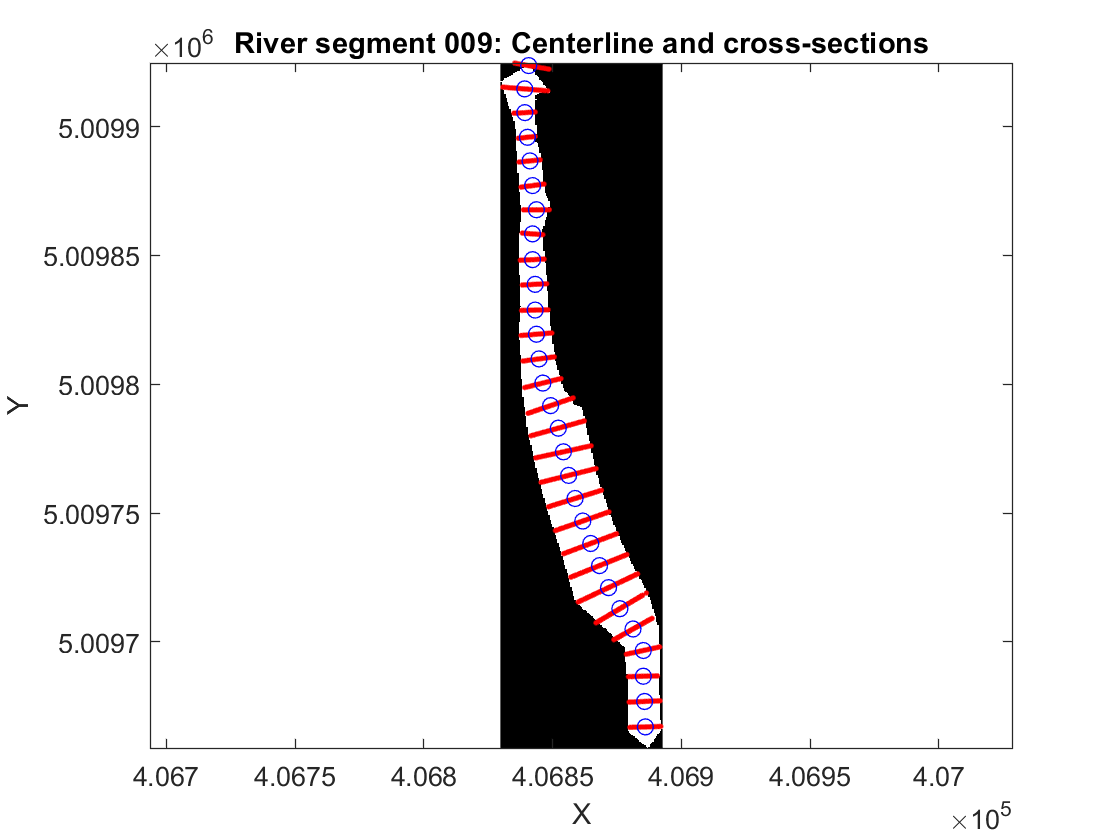

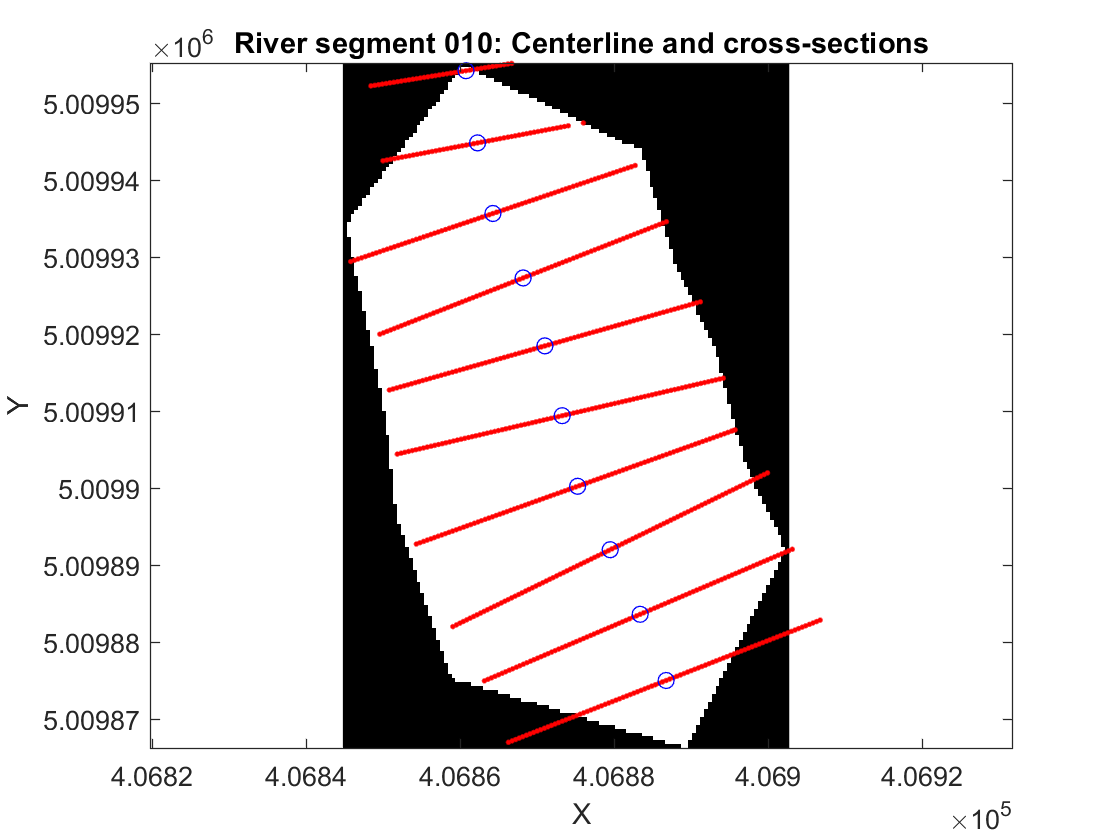

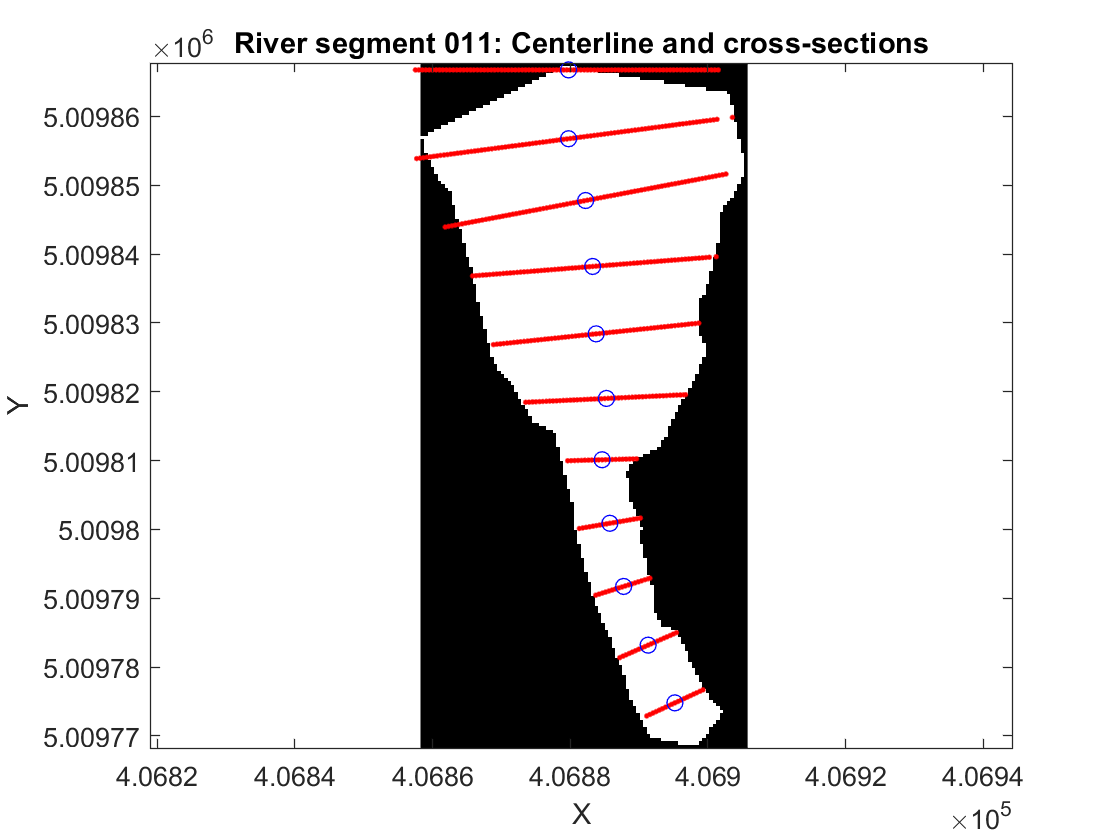

ans = logical
   1


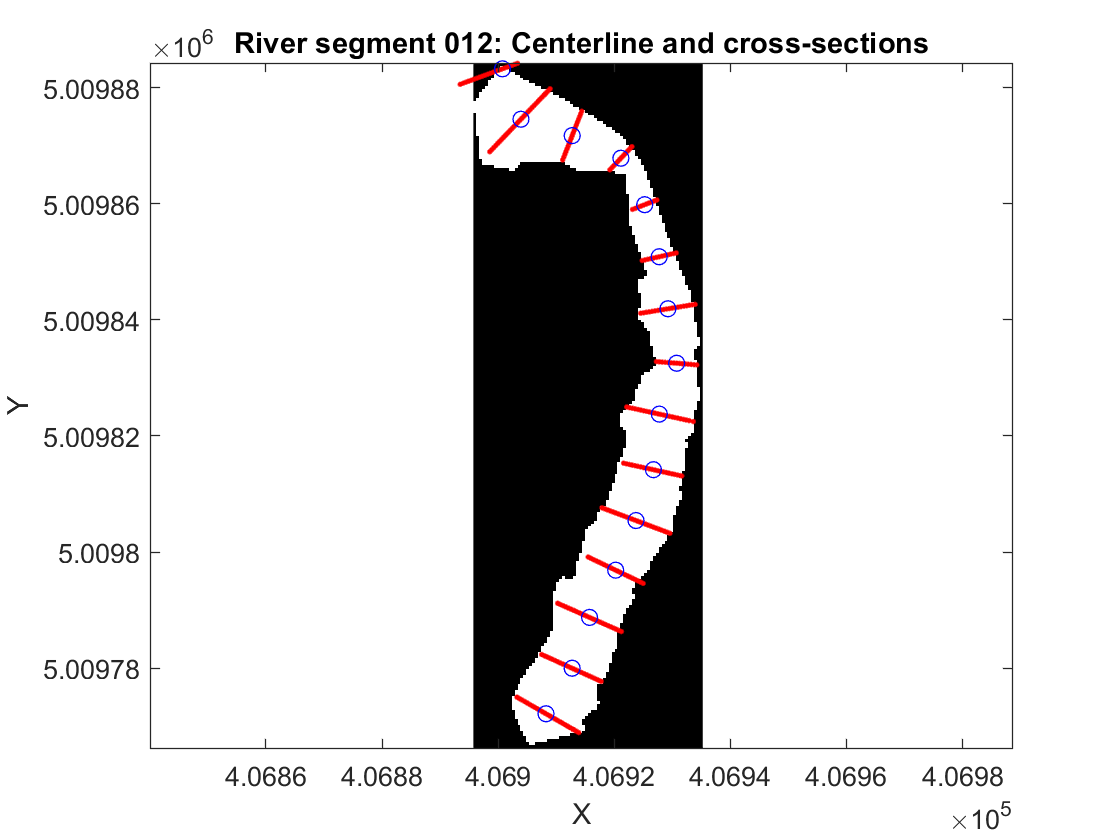

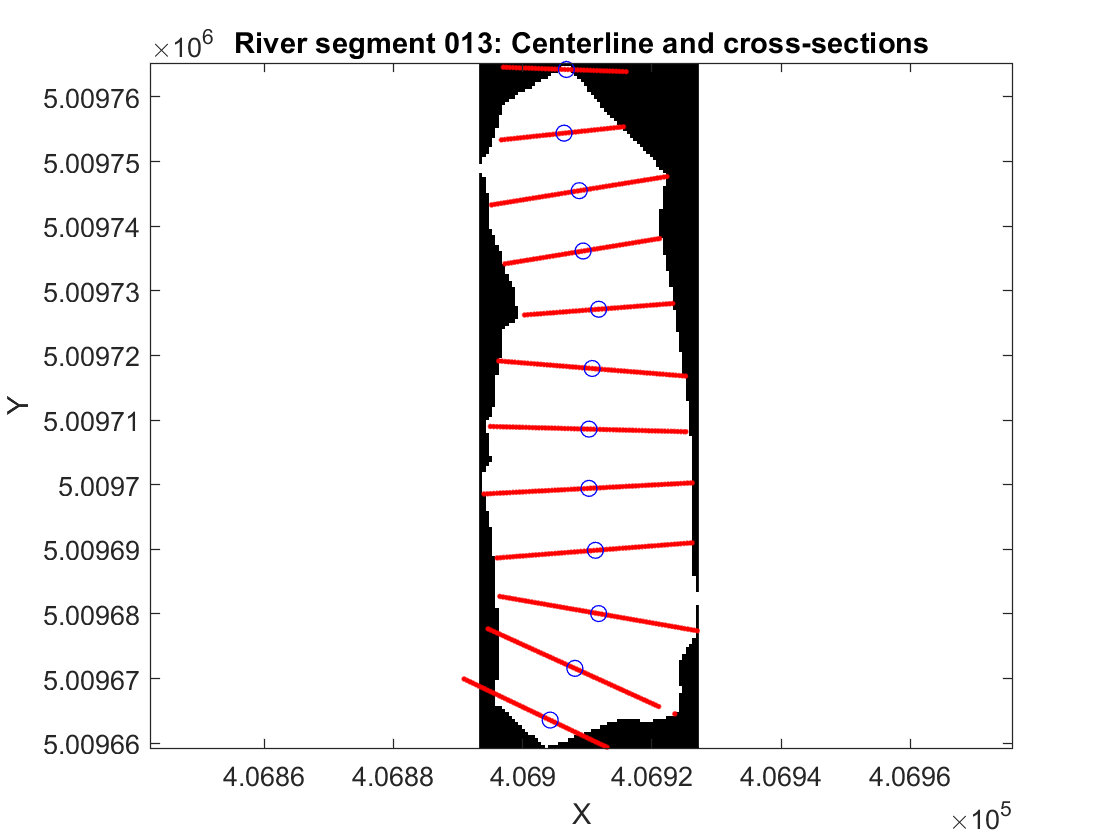

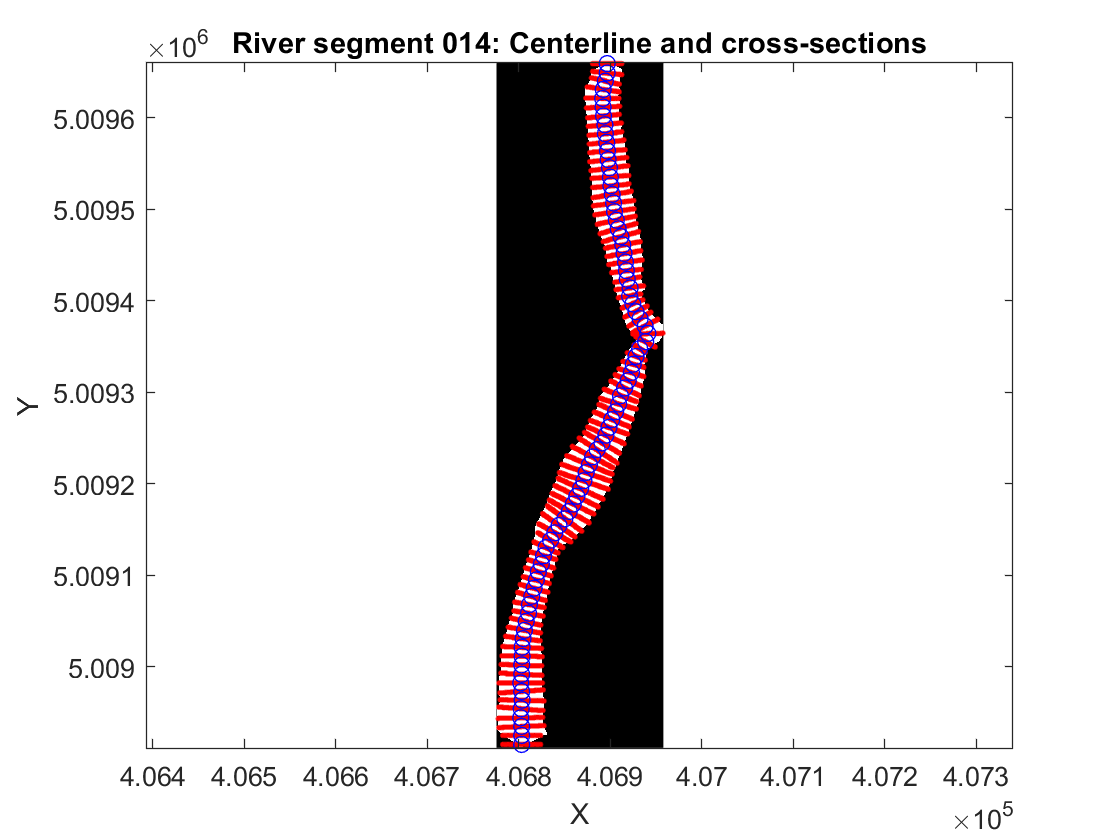

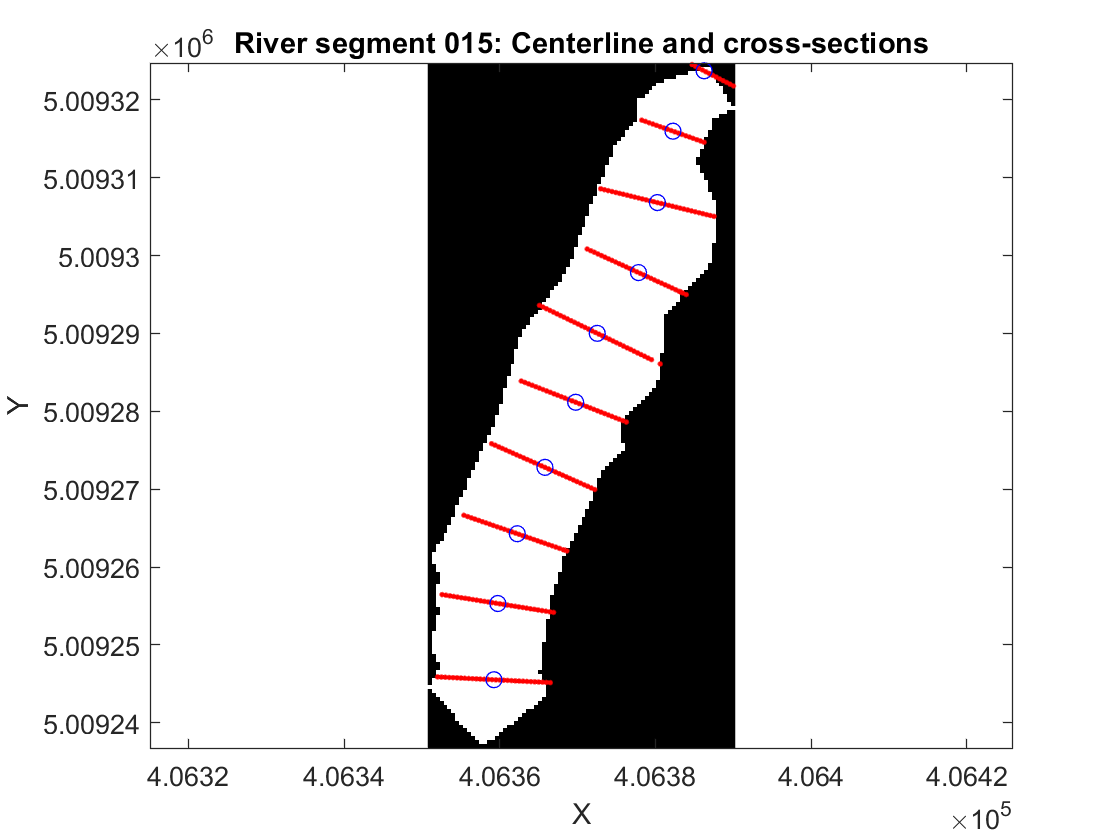

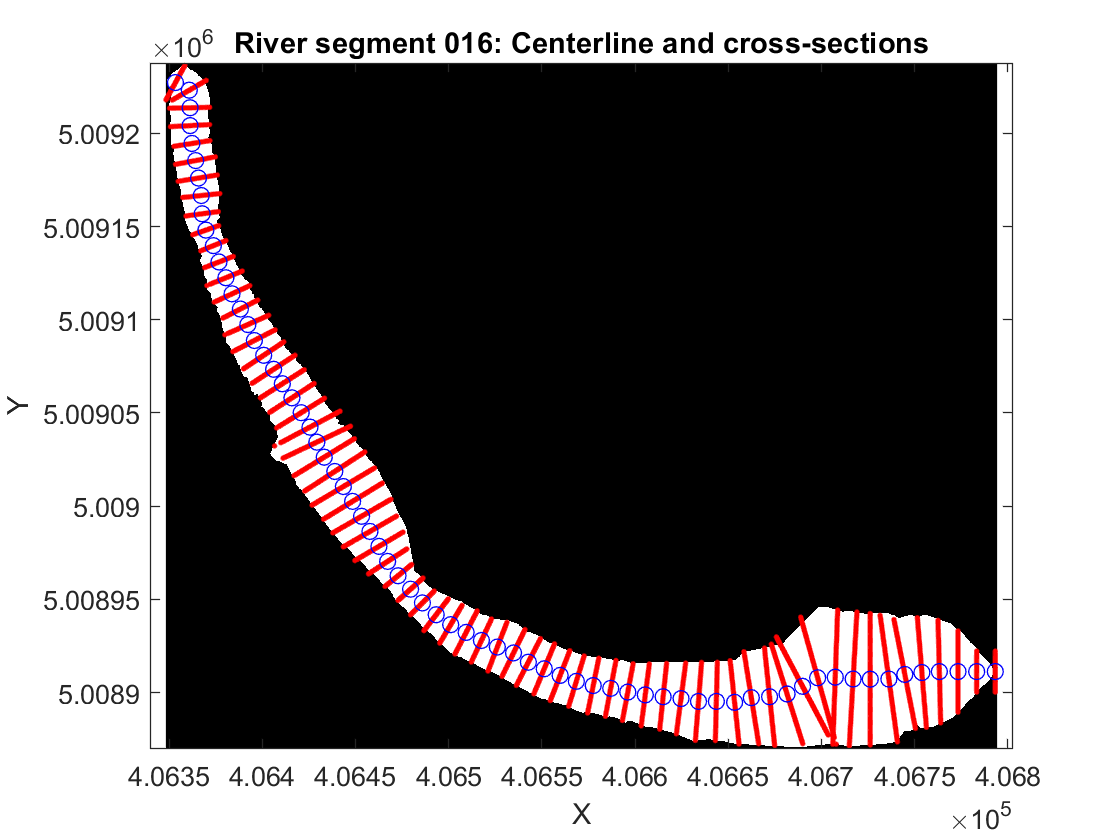

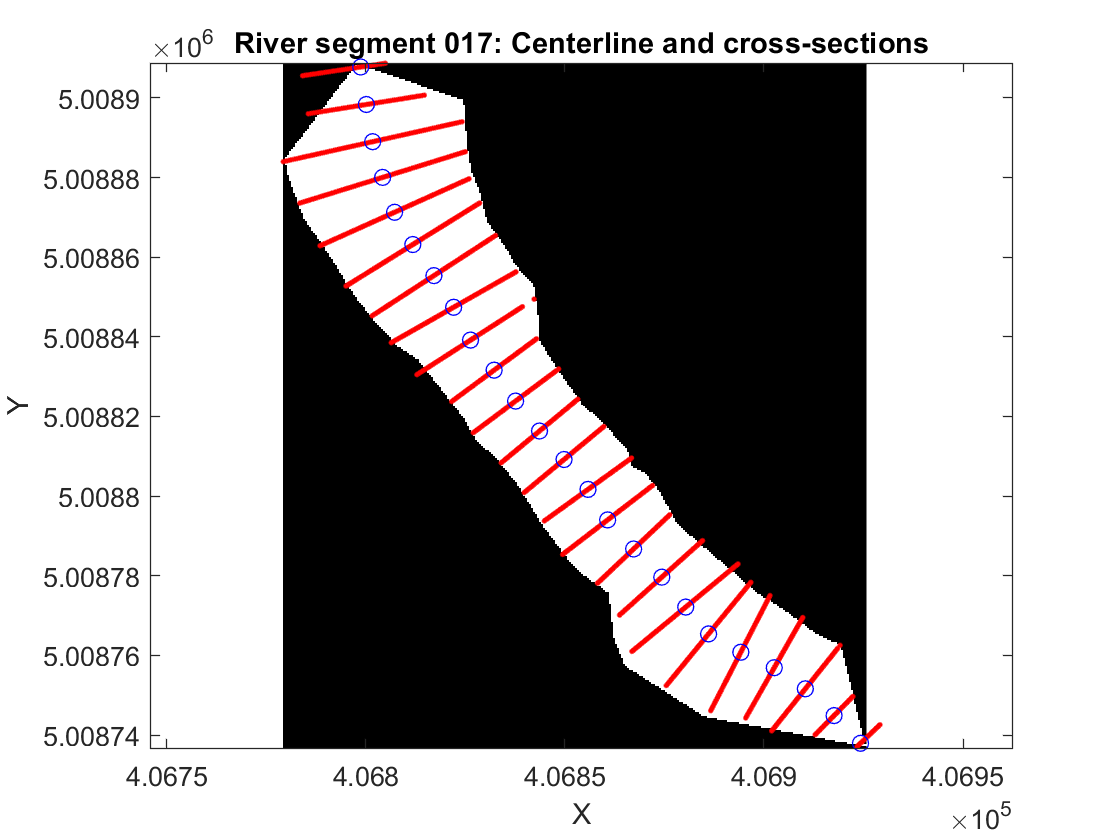

ans = logical
   1


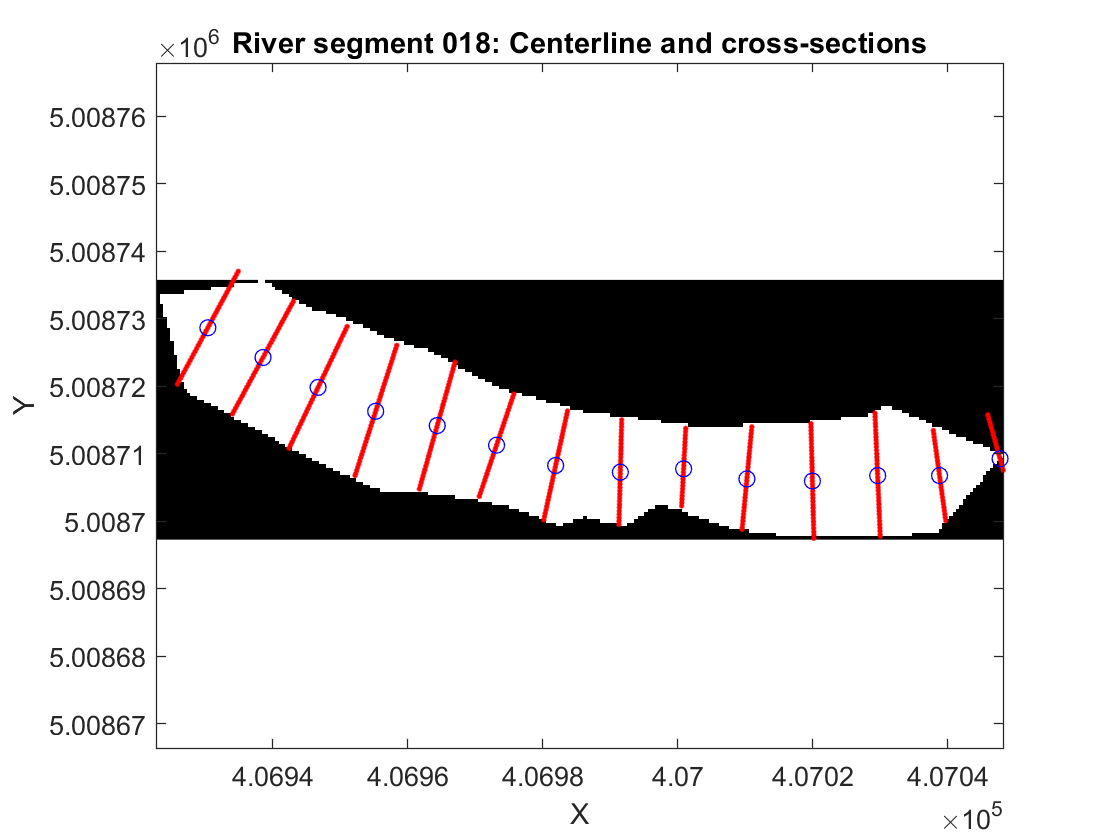

ans = logical
   1


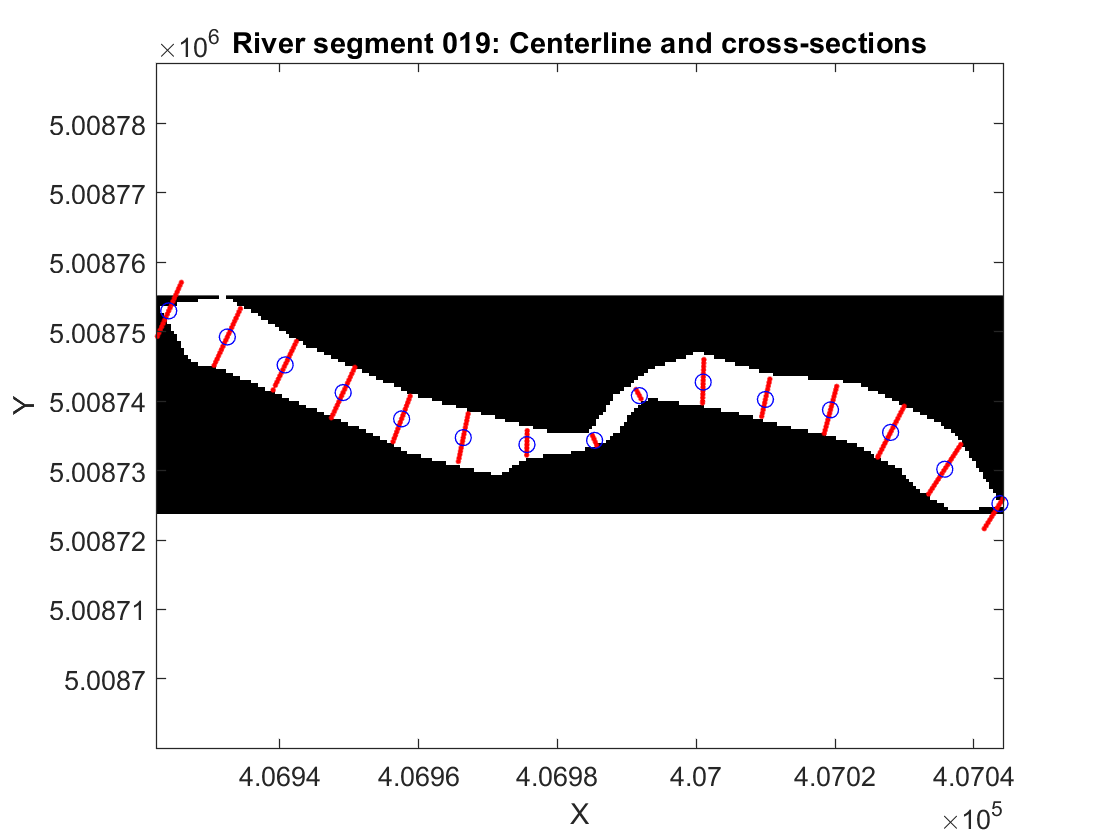

ans = logical
   1


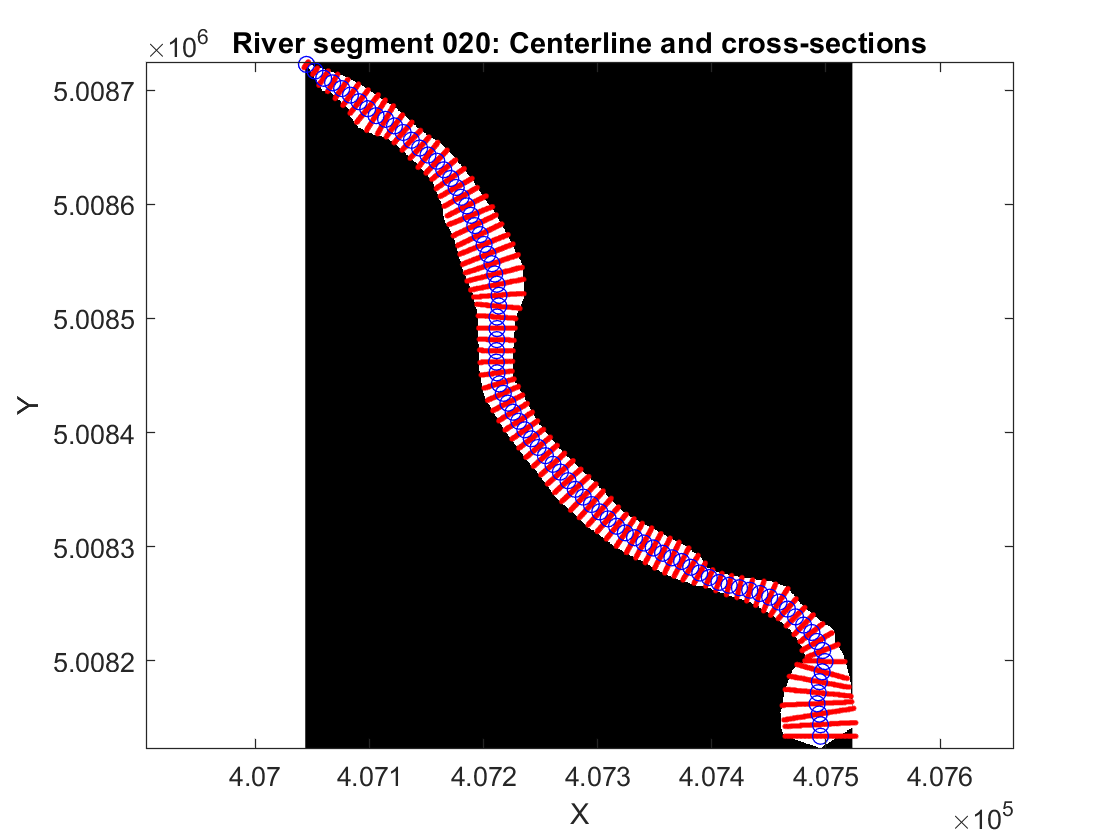

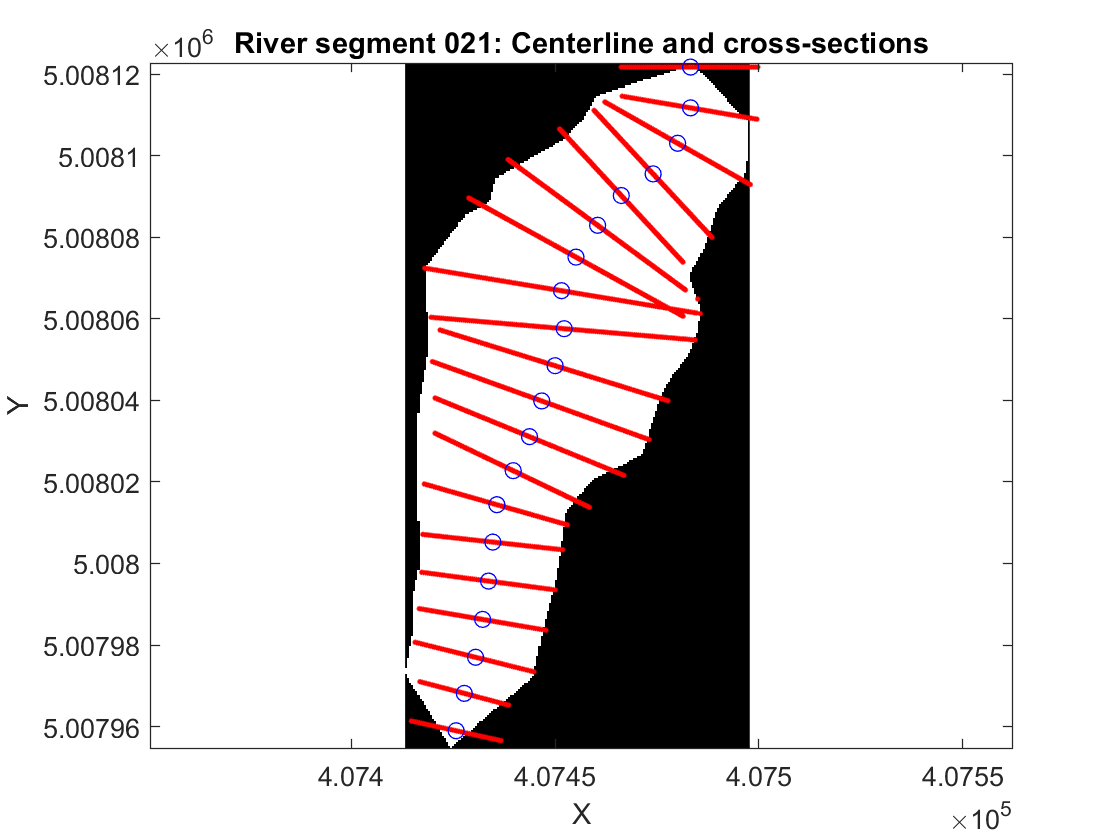

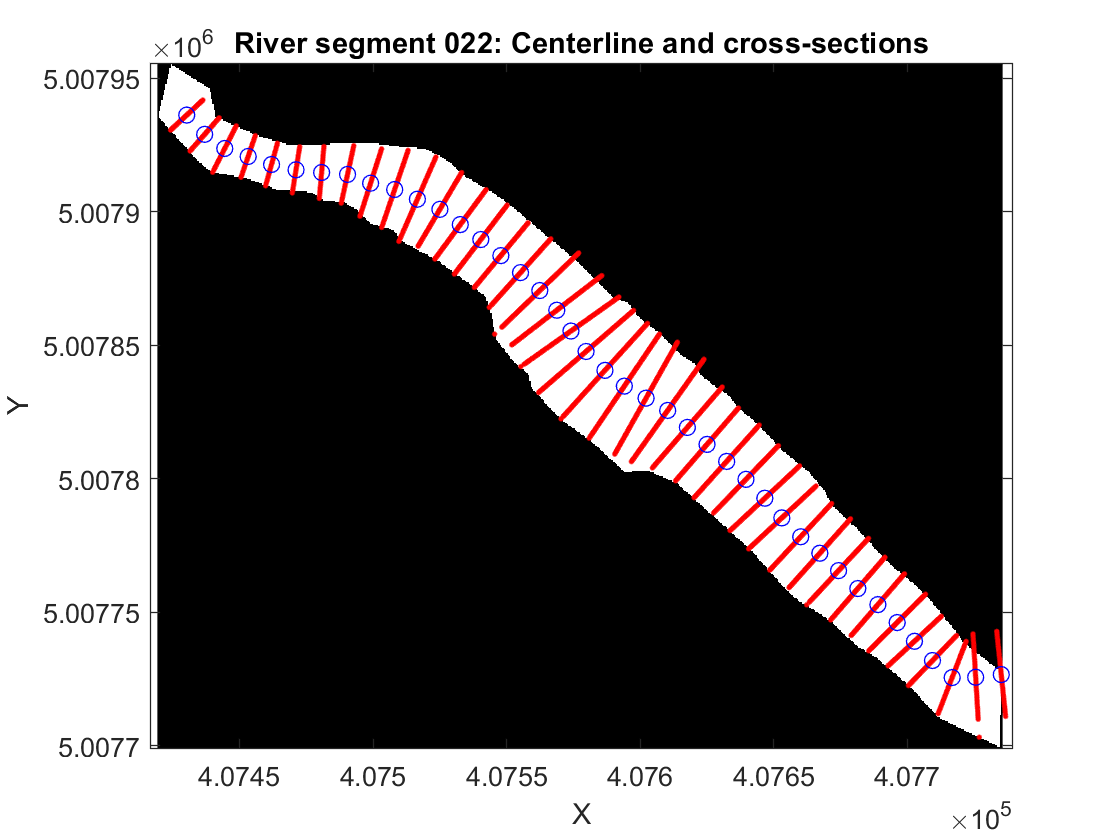

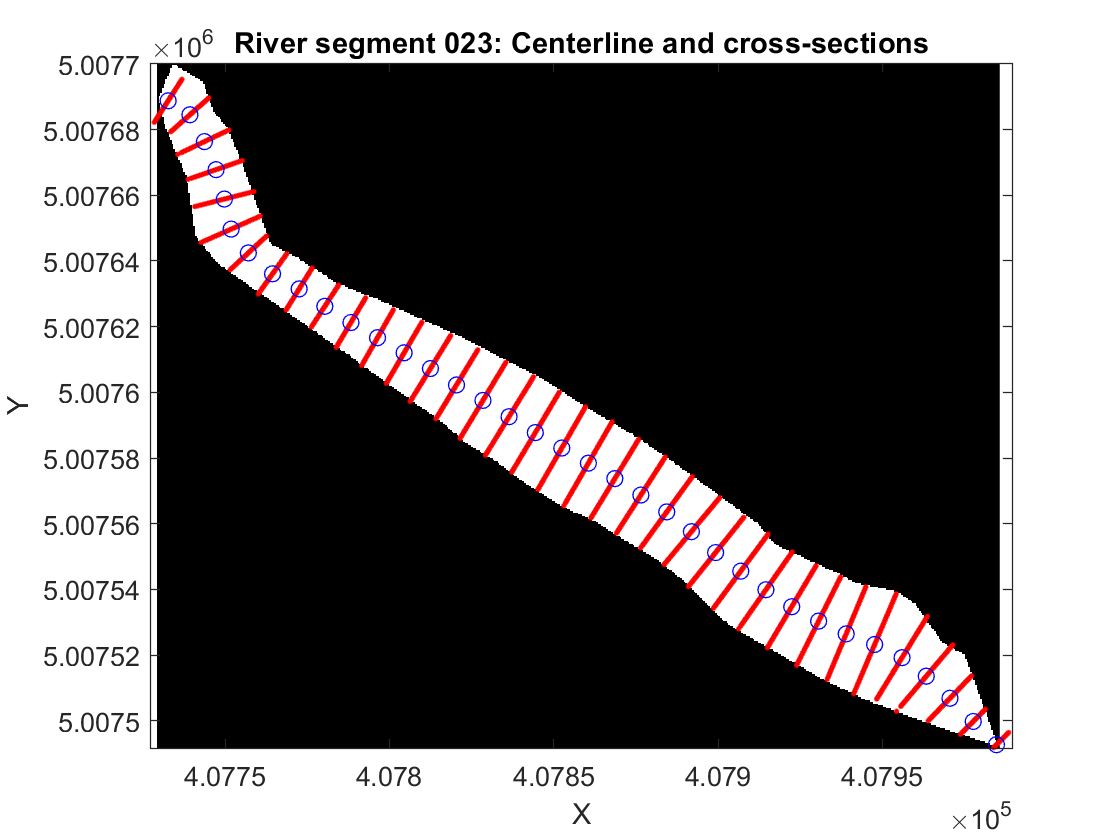

ans = logical
   1


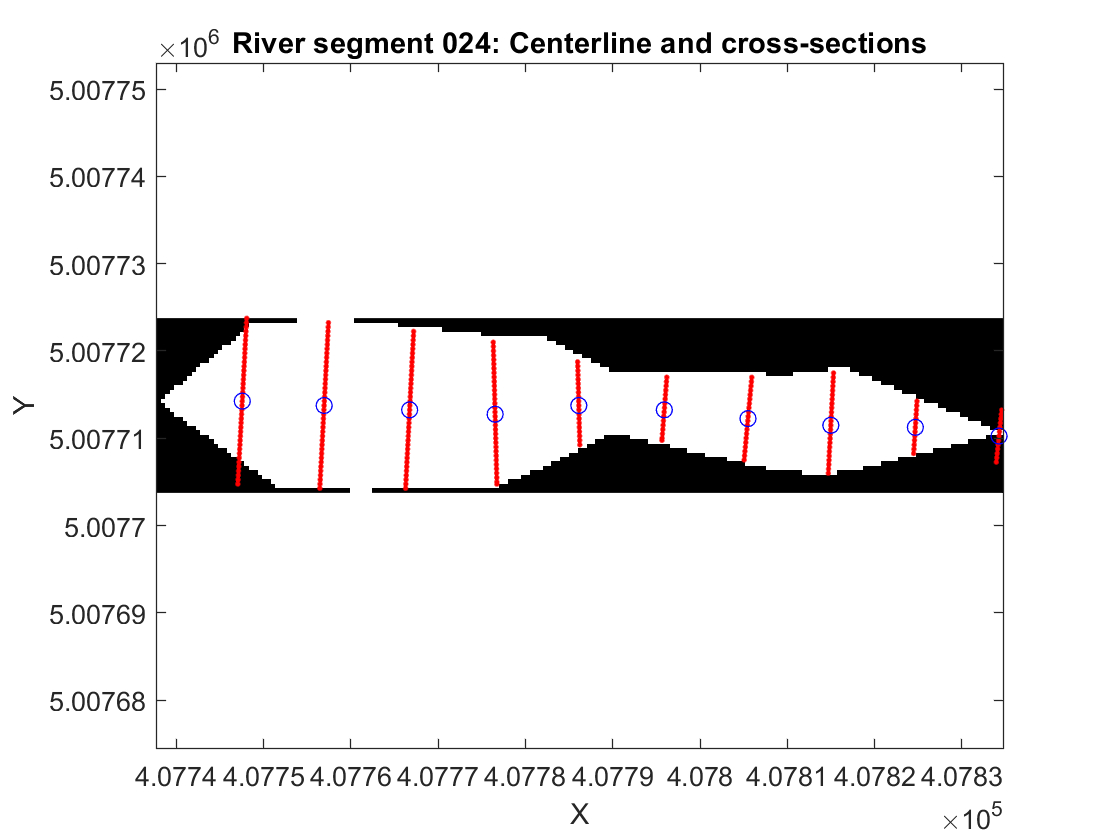

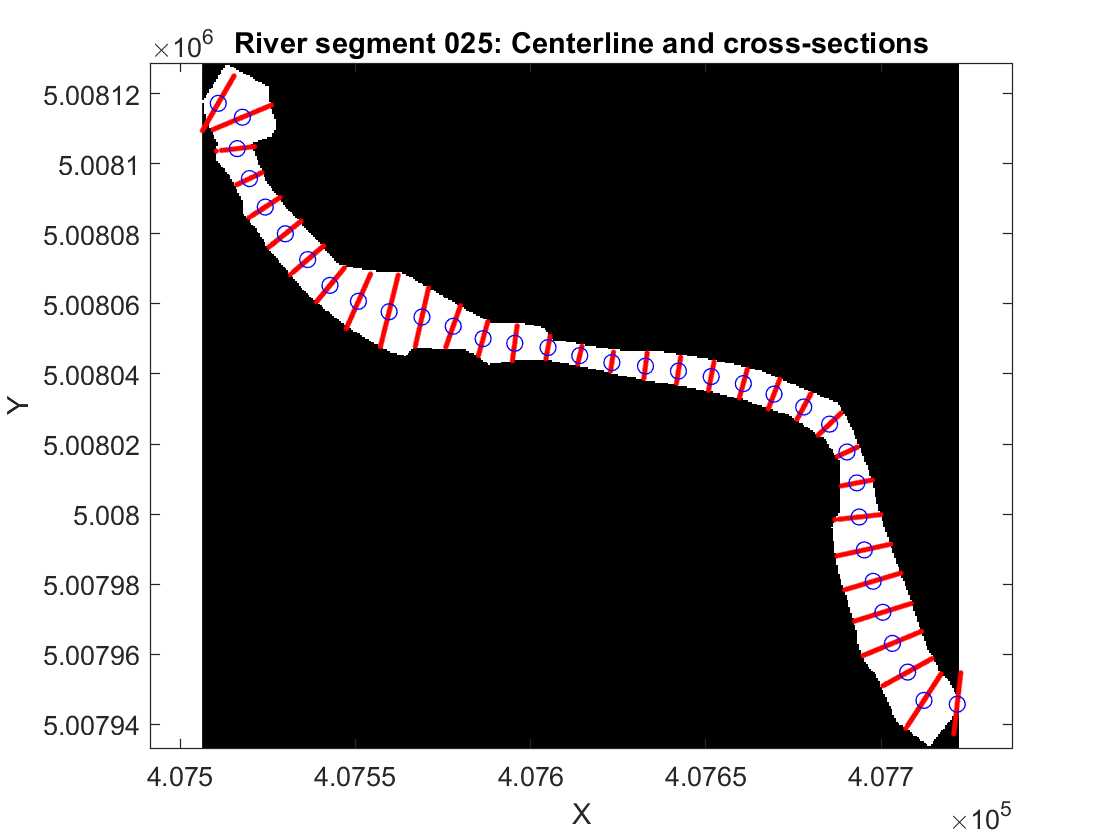

ans = logical
   1


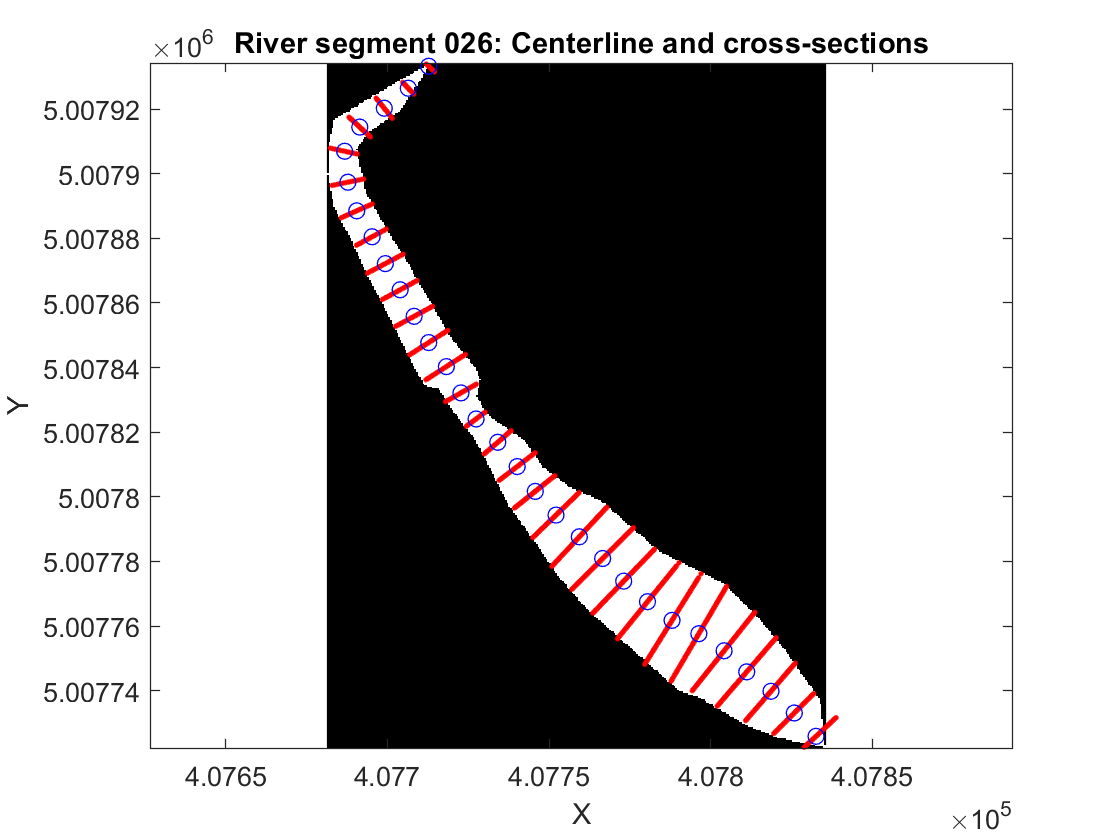

ans = logical
   1


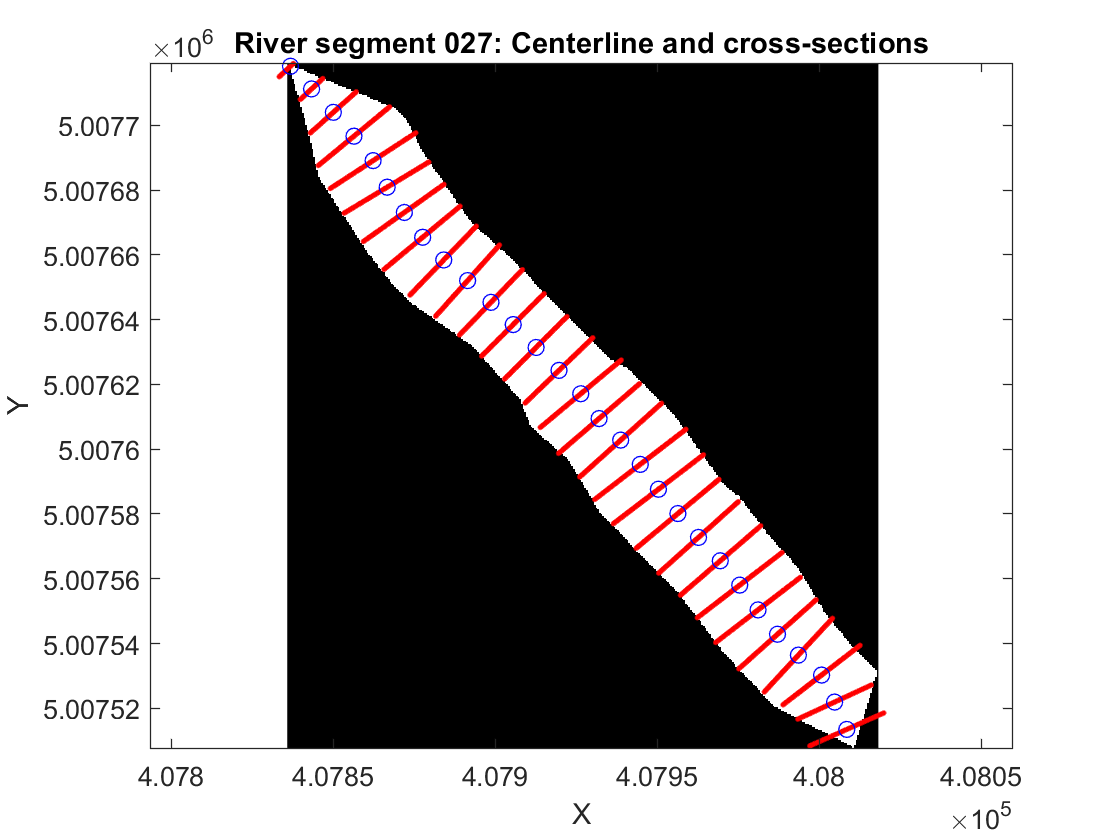

ans = logical
   1


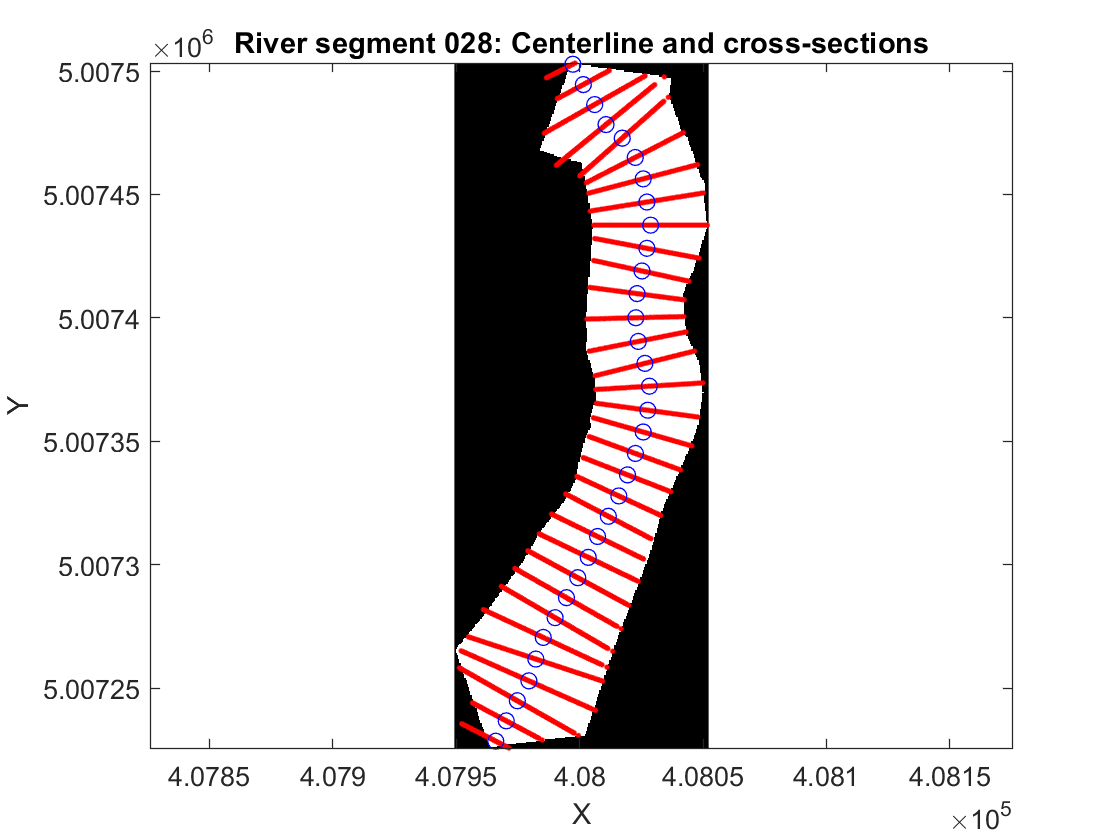

ans = logical
   1


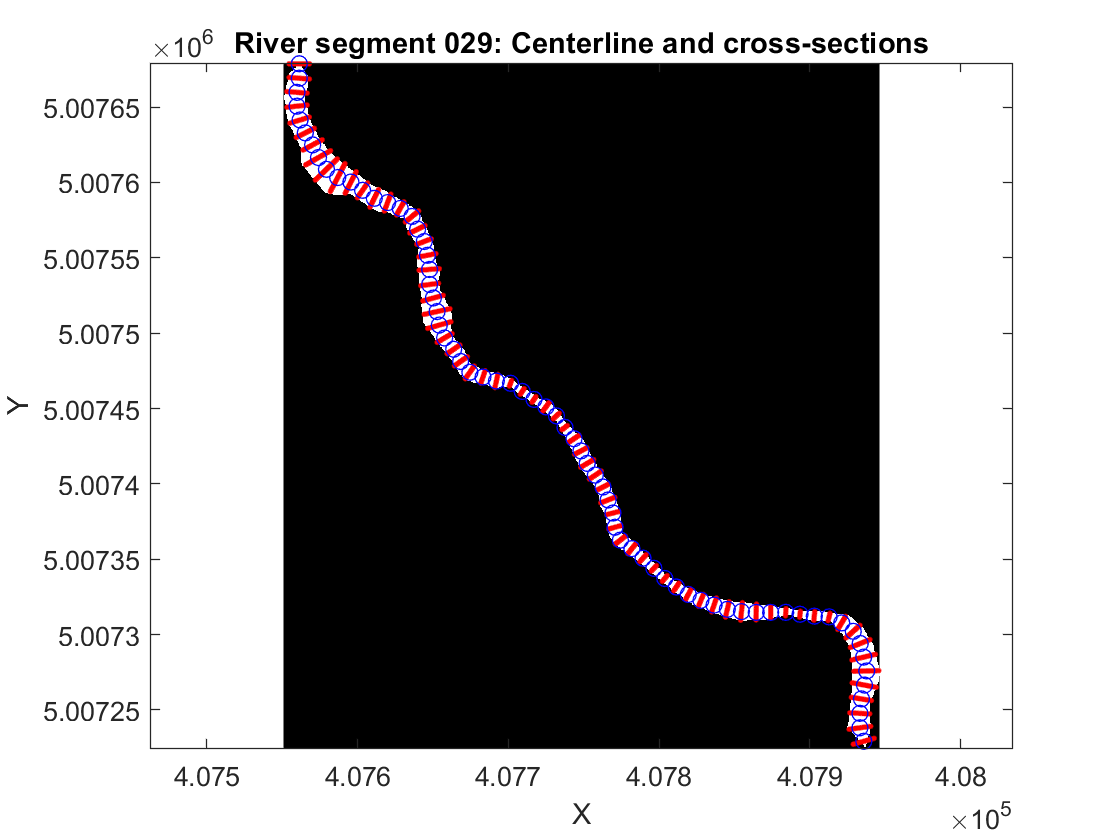

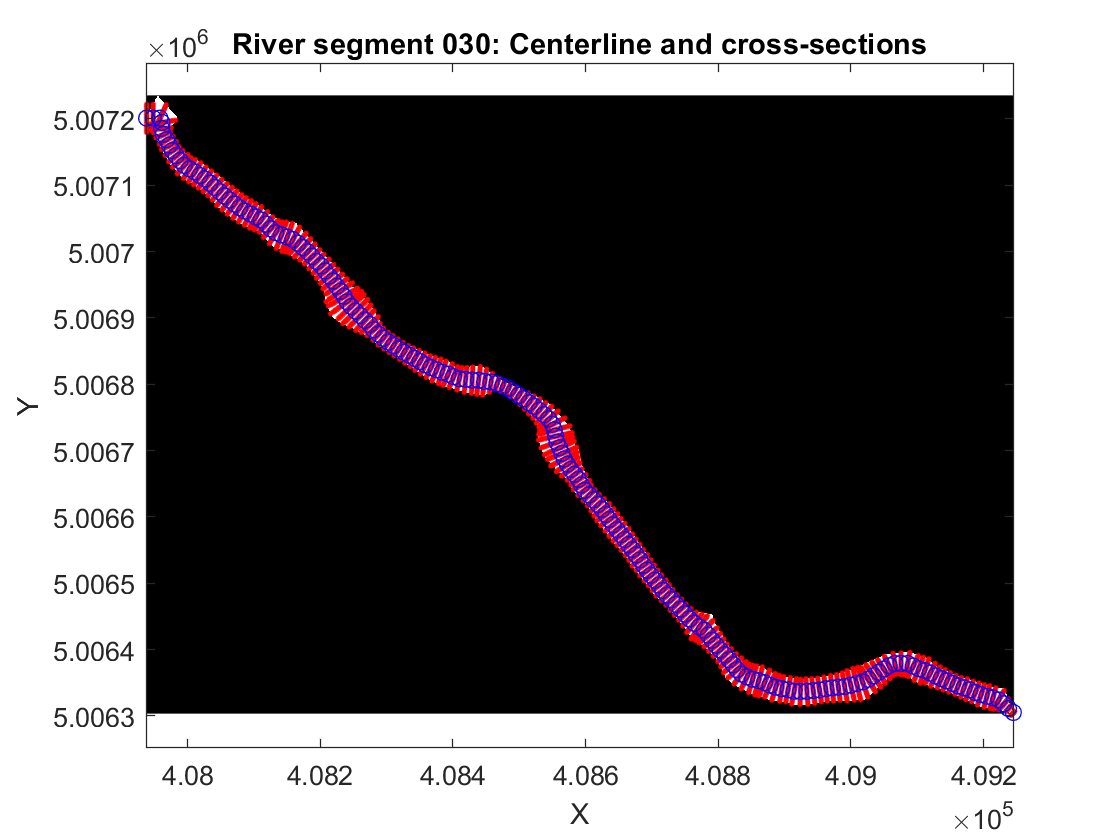

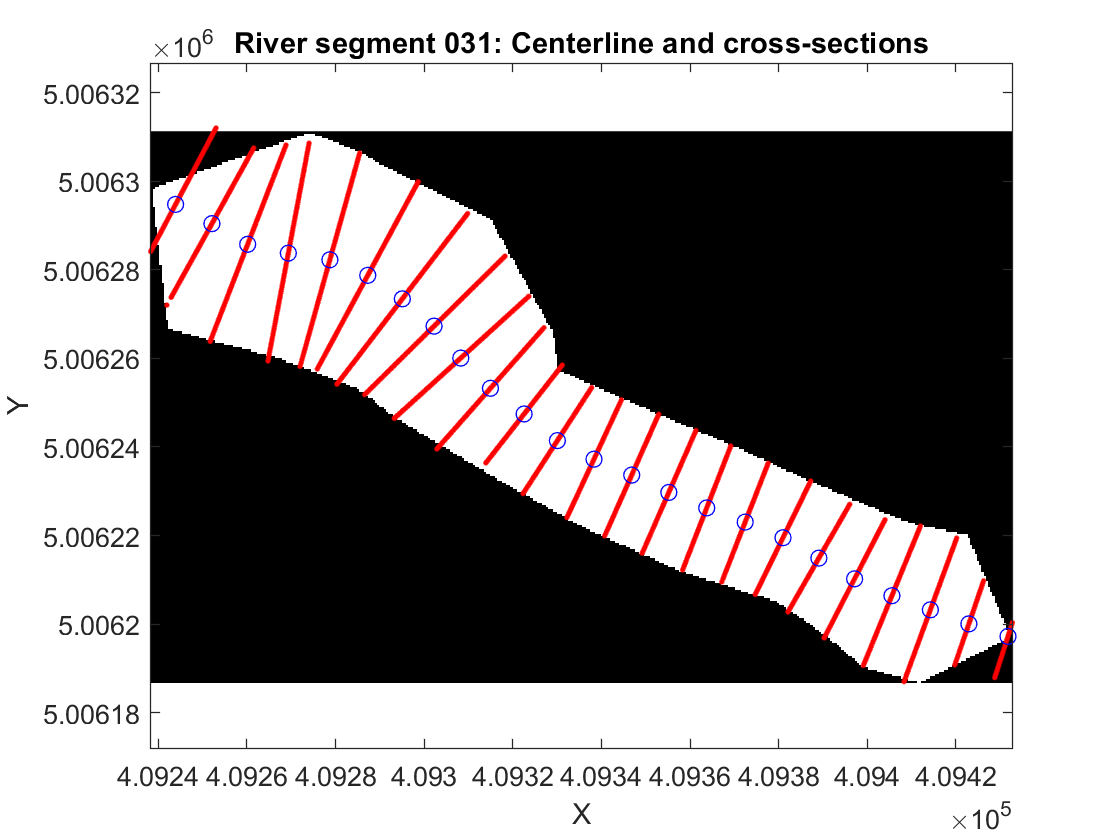

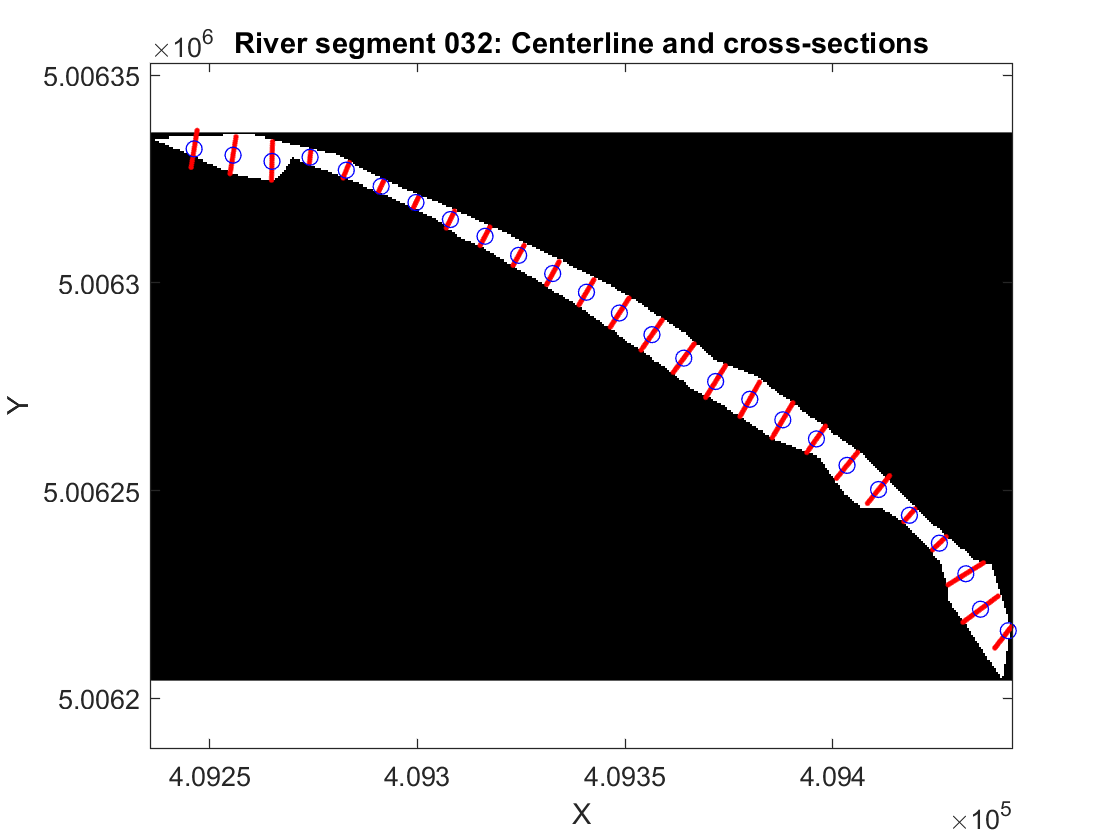

ans = logical
   1


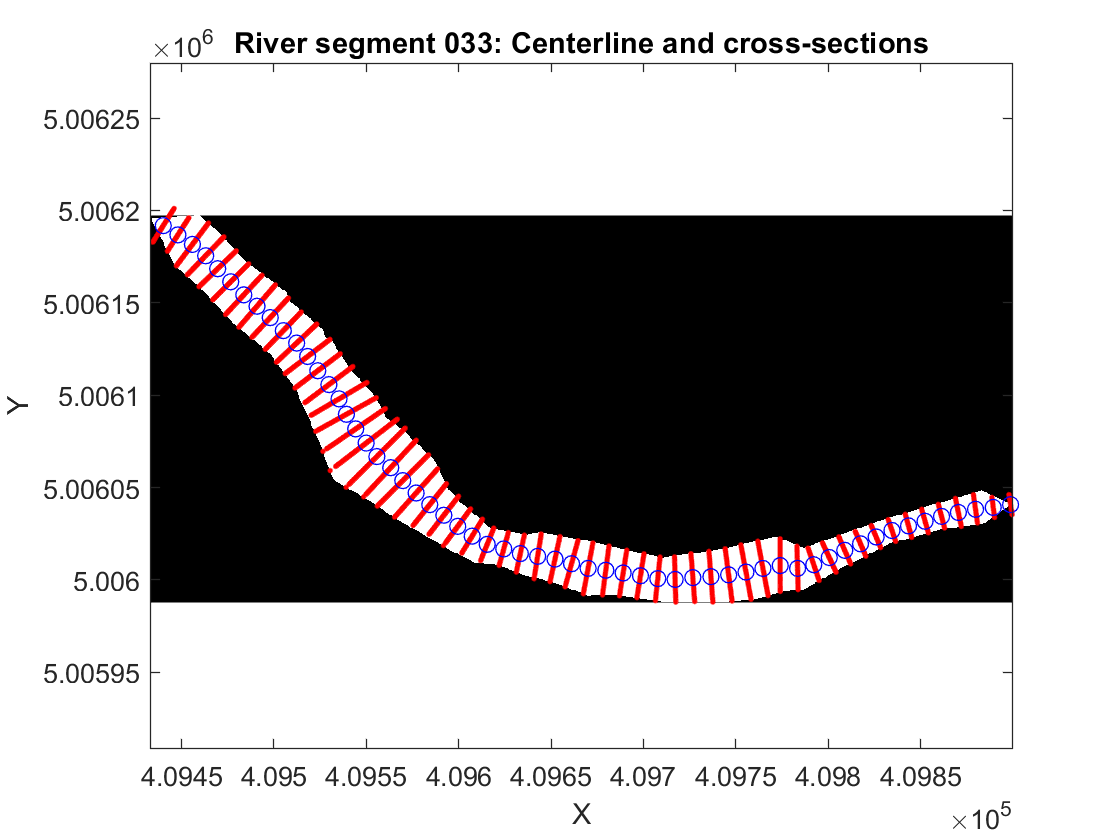

ans = logical
   1


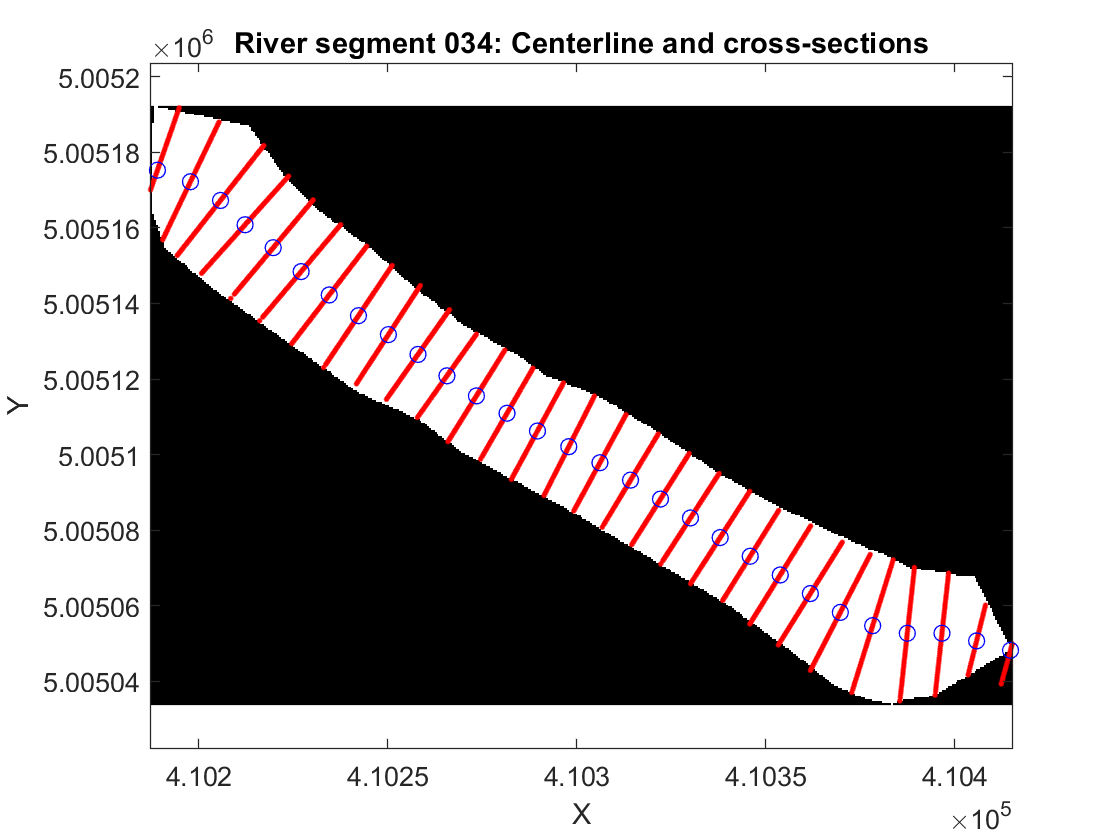

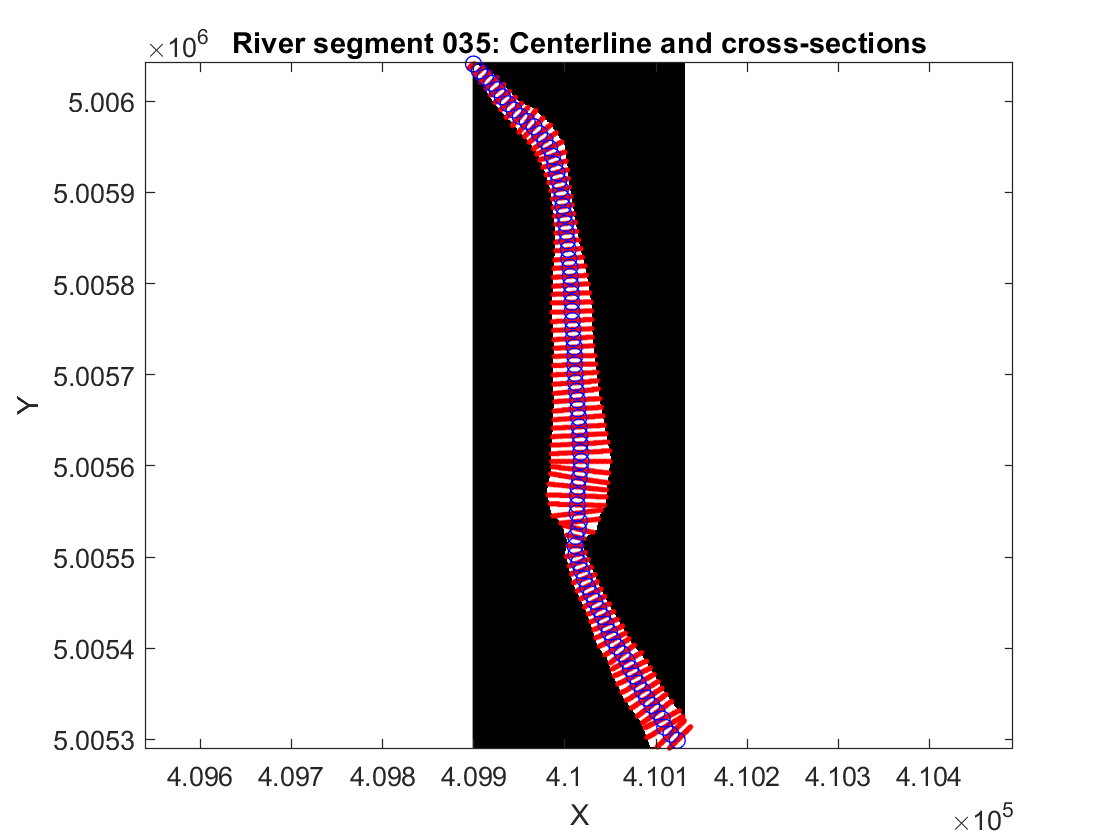

ans = logical
   1


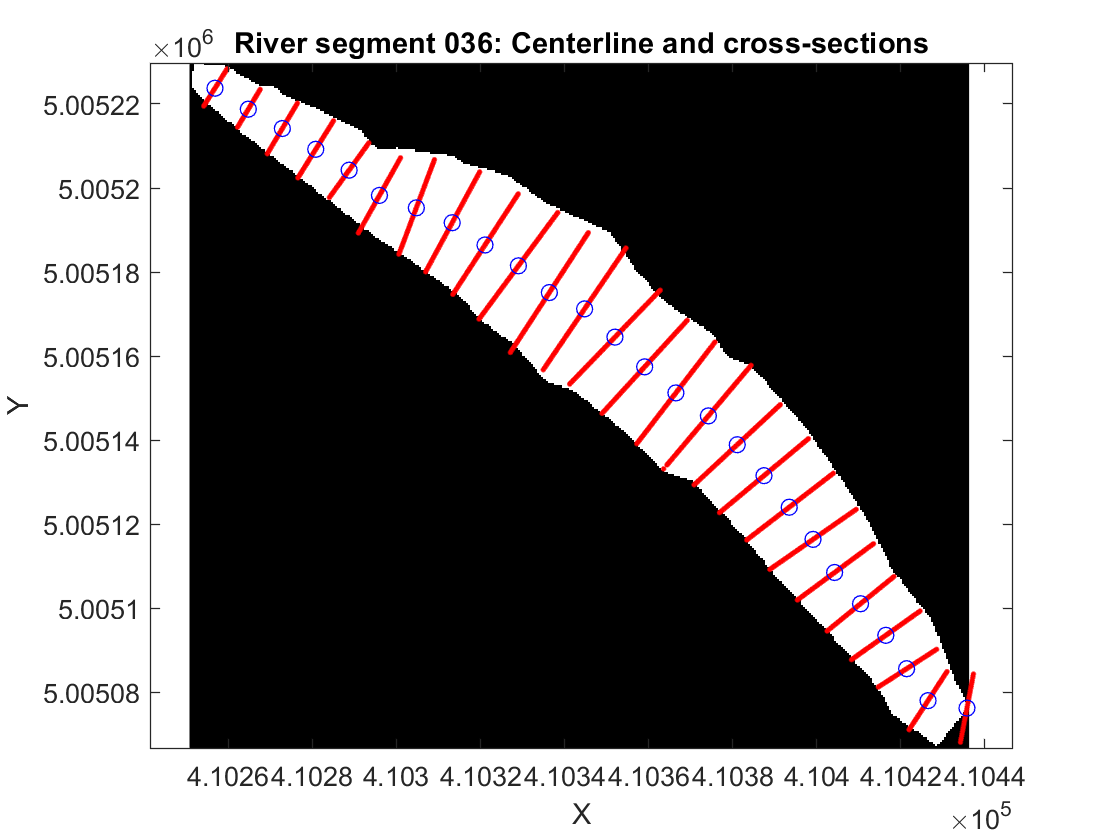

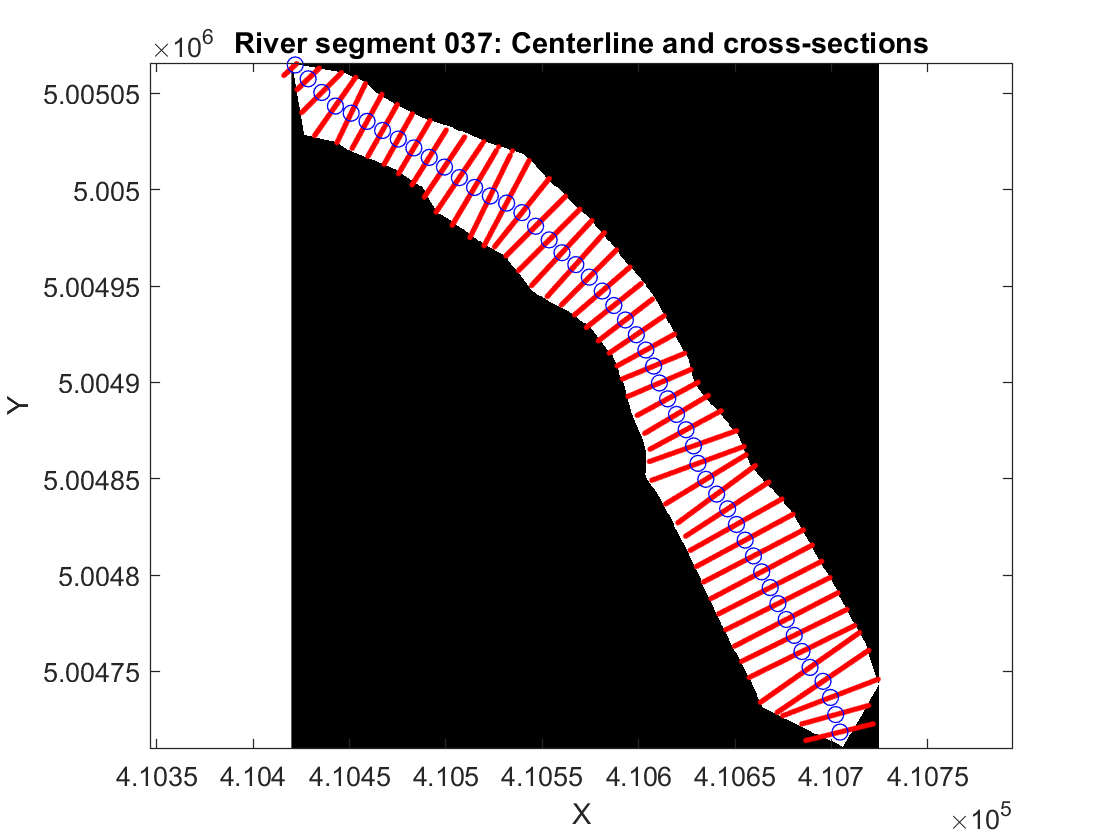

ans = logical
   1


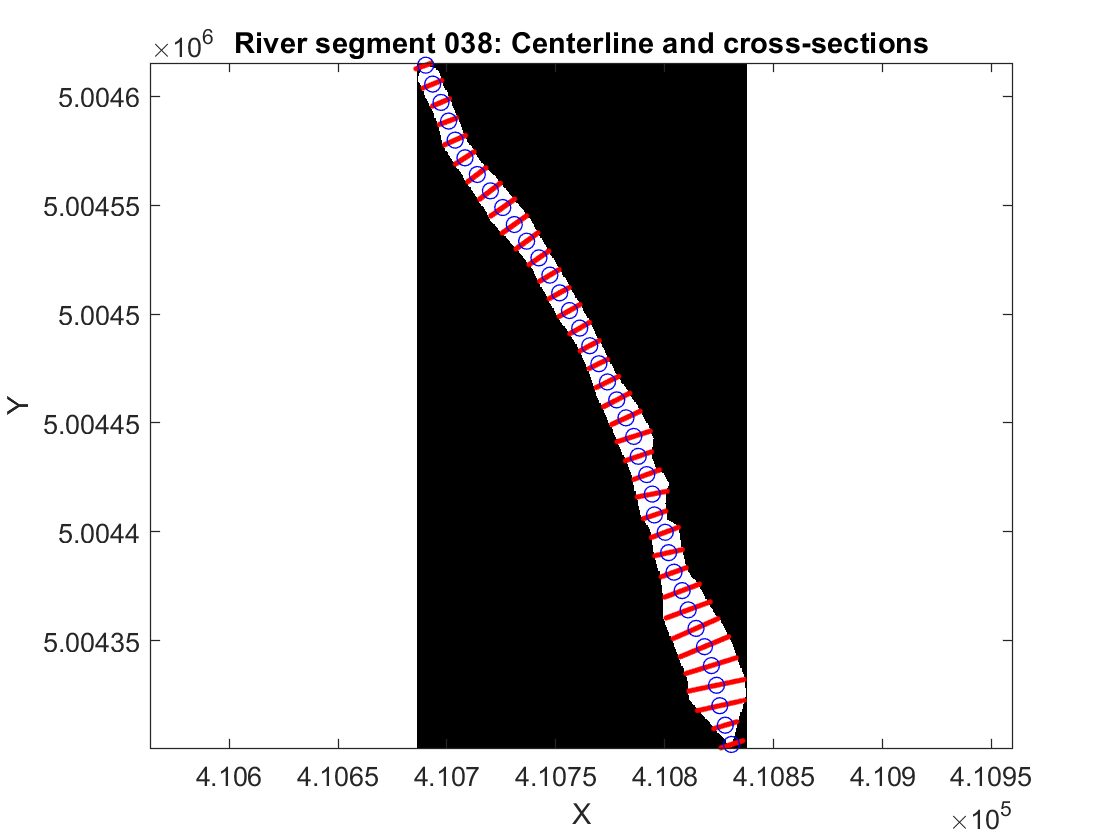

ans = logical
   1


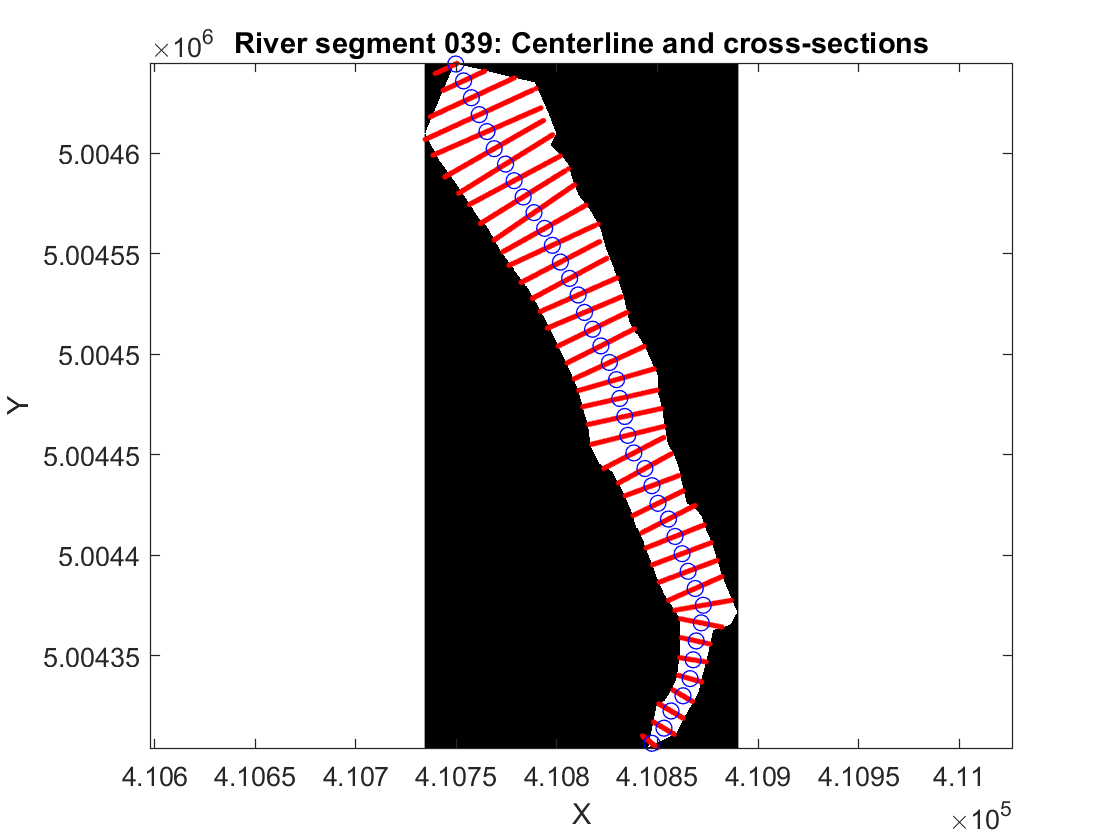

ans = logical
   1


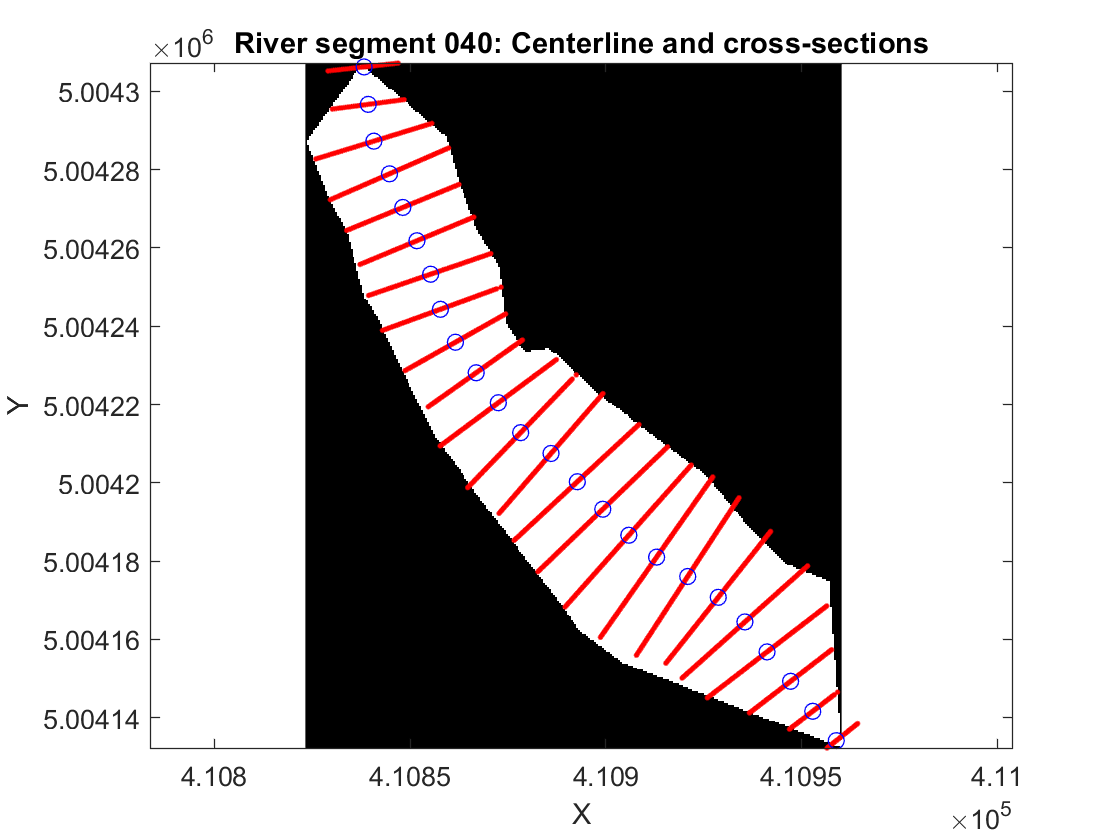

ans = logical
   1


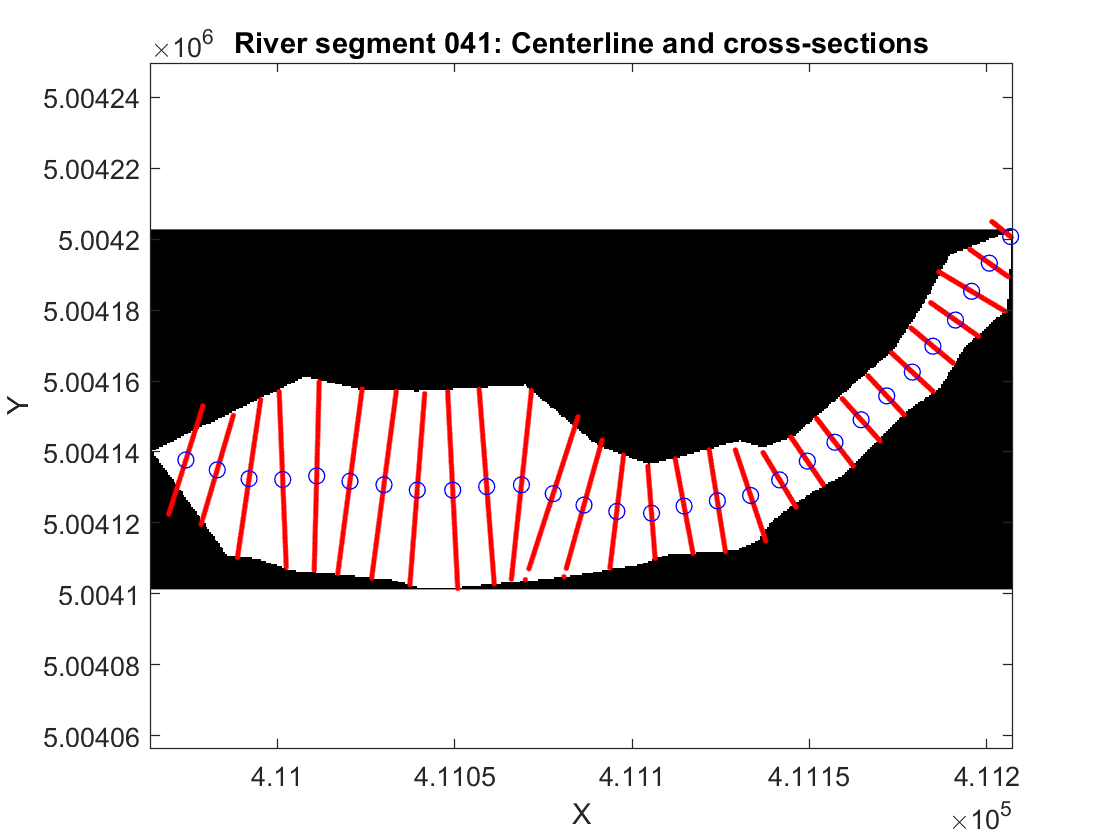

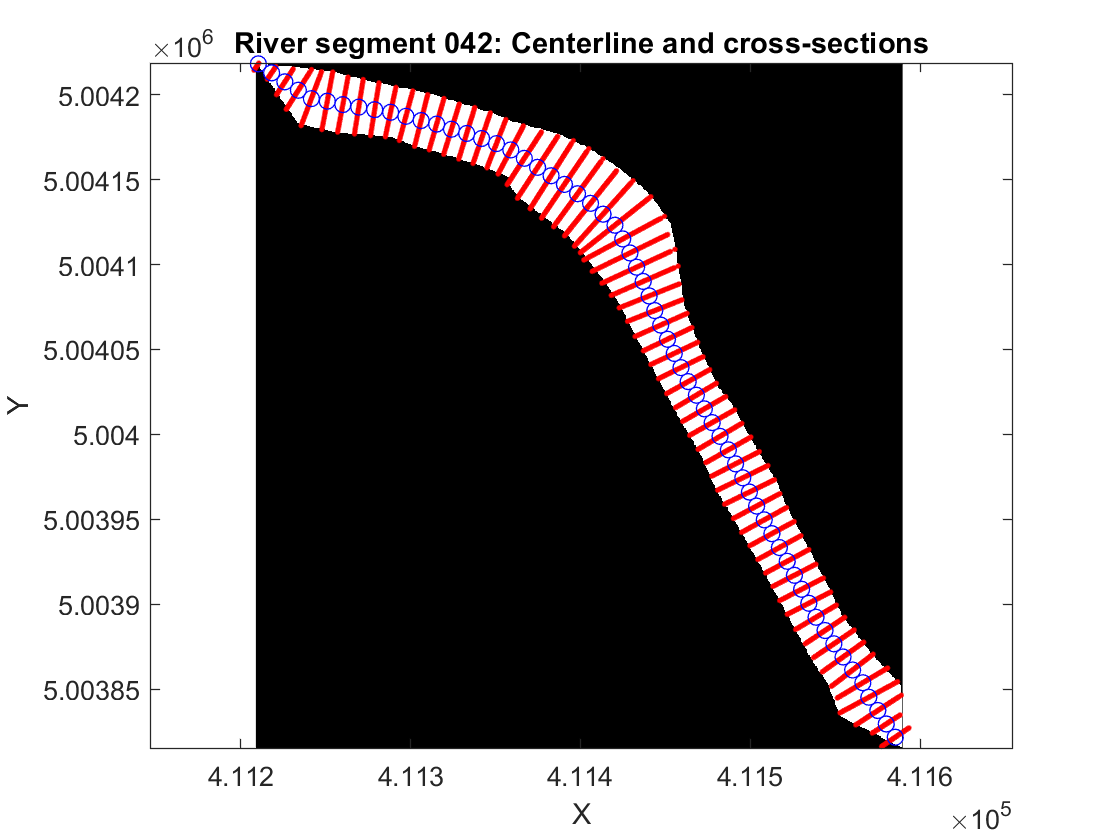

dtm_dir = '\\nas-camporeale\home\ELISA\BATHIMETRY\2025_bat\dtm_filled';
mask_dir = '\\nas-camporeale\home\ELISA\BATHIMETRY\2025_bat\Binary_Mask';

addpath('\\nas-camporeale\home\ELISA\BATHIMETRY\RivMap');

plotornot = 0; % 1 = YES visualization; 0 = NO visualization
Wn = 30; % Nominal channel width (average)
dx = 10; % Cross-section interval


dtm_files = dir(fullfile(dtm_dir, 'dtm_*.tif'));
mask_files = dir(fullfile(mask_dir, 'I_*.tif'));

% Data structures
all_centerlines = []; % cross-sections IDs | 3 centerline coordinates | cross-sections widths | segment code
sections_ids = []; % Start and end IDs of each river segment
sections_ids_with_coords = []; % Start and end IDs with coordinates of each river segment
id_counter = 1;

x_matrix = [];
y_matrix = [];
z_matrix = [];
widths_all = []; 

% Iterations for the number of segments
for i = 1:length(dtm_files)
    
    dtm_path = fullfile(dtm_files(i).folder, dtm_files(i).name);
    mask_path = fullfile(mask_files(i).folder, mask_files(i).name);

    [dtm, R_dtm] = readgeoraster(dtm_path);
    [river_mask, R_mask] = readgeoraster(mask_path);

        dtm = double(dtm);
    
        % Nominal width conversion m --> pixels
    px_size_x = R_mask.CellExtentInWorldX;
    px_size_y = R_mask.CellExtentInWorldY;
    if abs(px_size_x - px_size_y) > 1e-6
        warning('Pixel non quadrati nella maschera %s (dx=%.3f, dy=%.3f m): uso la media.', ...
            mask_files(i).name, px_size_x, px_size_y);
    end
    px_size = mean([px_size_x, px_size_y]);   % m/pixel
    
    Wn_px = Wn / px_size;                     % Larghezza nominale in PIXEL
    
    if Wn_px < 3
        warning('Wn_px = %.1f px per %s: soglia di pulizia scheletro molto bassa, verificare la risoluzione.', ...
            Wn_px, mask_files(i).name);
    end
    
    % River segment edges
    [row, col] = find(river_mask > 0); 
    x_coords = R_mask.XWorldLimits(1) + col * R_mask.CellExtentInWorldX;
    y_coords = R_mask.YWorldLimits(2) - row * R_mask.CellExtentInWorldY;

    % River segment orientation
    delta_x = max(x_coords) - min(x_coords);
    delta_y = max(y_coords) - min(y_coords);

    if delta_y > delta_x
        es = 'NS'; 
    else
        es = 'EW';
    end

    % Centerline calculation
    [cl, ~] = centerline_from_mask_modifiche(river_mask, es, Wn_px, plotornot);

    [x_cl, y_cl] = intrinsicToWorld(R_mask, cl(:, 1), cl(:, 2));
    x_world = linspace(R_mask.XWorldLimits(1), R_mask.XWorldLimits(2), size(river_mask, 2));
    y_world = linspace(R_mask.YWorldLimits(2), R_mask.YWorldLimits(1), size(river_mask, 1));


    z_cl = interp2(x_world, y_world, dtm, x_cl, y_cl, 'linear');
    xyz_cl = [x_cl, y_cl, z_cl];

    dist_cum = [0; cumsum(sqrt(sum(diff(xyz_cl(:, 1:2)).^2, 2)))];
    dist_interp = 0:dx:dist_cum(end);
    x_interp = interp1(dist_cum, xyz_cl(:, 1), dist_interp, 'linear');
    y_interp = interp1(dist_cum, xyz_cl(:, 2), dist_interp, 'linear');
    z_interp = interp1(dist_cum, xyz_cl(:, 3), dist_interp, 'linear');
    for j = 1:length(z_interp)
        if z_interp(j) < 0
            if j > 1 && z_interp(j-1) >= 0
                z_interp(j) = z_interp(j-1);  
            elseif j < length(z_interp) && z_interp(j+1) >= 0
                z_interp(j) = z_interp(j+1);  % altrimenti assegna valore successivo
            end
        end
    end

    % Verify upstream-downstream direction of river segments
    if z_interp(1) < z_interp(end)
        x_interp = flipud(x_interp);
        y_interp = flipud(y_interp);
        z_interp = flipud(z_interp);
    end
    
    num_points = length(x_interp);
    [~, mask_name, ~] = fileparts(mask_files(i).name);
    mask_code = extractAfter(mask_name, 'I_'); % Cross-section number extraction (es. '000','001', etc)
    segment_code = str2double(mask_code); % (000 -> 0, etc.)
    segment_codes = repmat(segment_code, num_points, 1); % same code for all segment's points 
    % Assign IDs
    ids = (id_counter:id_counter + num_points - 1)'; 
    id_counter = id_counter + num_points;

    % Width calculation
    [widths, sect_x, sect_y, sect_z, z_sect_mean] = calculate_widths(... 
        x_interp, y_interp, z_interp, x_world, y_world, river_mask, dtm);
    widths_all = vertcat(widths_all, widths(:)); 
    x_matrix = vertcat(x_matrix, sect_x); 
    y_matrix = vertcat(y_matrix, sect_y); 
    z_matrix = vertcat(z_matrix, sect_z); 
     
    % Plot binary mask of each river segment with centerline and cross-sections 
    figure;
    imagesc(R_mask.XWorldLimits, R_mask.YWorldLimits, flipud(river_mask));
    colormap('gray');
    set(gca, 'YDir', 'normal'); 
    hold on;

    % Plot cross-sections
    [r, ~] = size(sect_x);
    for j = 1:r
    plot(sect_x(j, :), sect_y(j, :), '.r');
    hold on;
    end

    % Plot centerline
    plot(x_interp, y_interp, 'ob');

    title(sprintf('River segment %s: Centerline and cross-sections', mask_code));
    xlabel('X');
    ylabel('Y');
    axis equal;
    hold off;
    pause(1);

    % Be sure to have column vectors
    ids = ids(:);
    x_interp = x_interp(:);
    y_interp = y_interp(:);
    z_interp = z_interp(:);
    widths = widths(:);

    widths(isnan(widths)) = 0;
    all_centerlines = [all_centerlines; ...
    ids, x_interp, y_interp, z_sect_mean, widths, segment_codes];
    sections_ids = [sections_ids; ids(1), ids(end)];
    start_coords = [x_interp(1), y_interp(1), z_interp(1)];
    end_coords = [x_interp(end), y_interp(end), z_interp(end)];
    sections_ids_with_coords = [sections_ids_with_coords; ...
        ids(1), start_coords, ids(end), end_coords];
end


% % Save results
% writematrix(all_centerlines, 'all_centerlines_with_widths.txt', 'Delimiter', '\t');
% writematrix(sections_ids_with_coords, 'sections_ids_with_coords.txt', 'Delimiter', '\t');

disp('Done!');

Done!


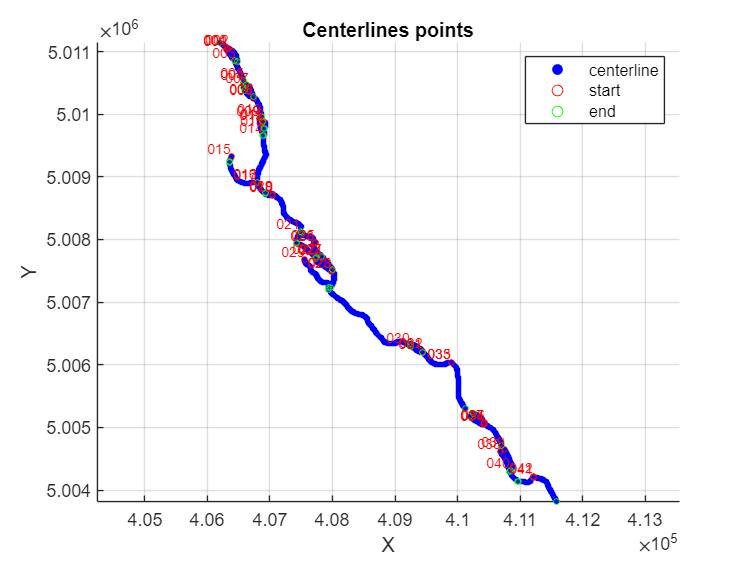

% 2D Plot
x_coords = all_centerlines(:, 2);
y_coords = all_centerlines(:, 3);
z_coords = all_centerlines(:, 4);

x_start = sections_ids_with_coords(:, 2);
y_start = sections_ids_with_coords(:, 3);
x_end = sections_ids_with_coords(:, 6);
y_end = sections_ids_with_coords(:, 7);

figure;
scatter(x_coords, y_coords, 10, 'b', 'filled');
title('Centerlines points');
xlabel('X');
ylabel('Y');
axis equal; 
grid on; 
hold on;
scatter(x_start, y_start, 10, 'or');
scatter(x_end, y_end, 10, 'og');
legend('centerline', 'start', 'end');

    mask_codes = strings(length(mask_files), 1); 

for i = 1:length(mask_files)
    [~, mask_name, ~] = fileparts(mask_files(i).name);
    mask_codes(i) = extractAfter(mask_name, 'I_'); 
end

if length(mask_codes) ~= length(x_start)
    error('Codes number is not equal to river segments!');
end

for i = 1:length(x_start)
    text(x_start(i), y_start(i), mask_codes(i), ...
    'FontSize', 8, 'Color', 'r', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
end
hold off;

% Aking the user to flip river segments
% UPSTREAM - DOWNSTREAM
% 2025: 000 006 015 018 019 022 023 024 025 029 030 031 032 033 034 036 041
invert_input = input('Are there river segments to flip (yes/no): ', 's');

if strcmpi(invert_input, 'yes')
    tratti_da_invertire = input('Write codes of river segments to flip (spaced): ', 's');
    tratti_da_invertire = strsplit(tratti_da_invertire); 
    
    for i = 1:length(tratti_da_invertire)
        codice_tratto = tratti_da_invertire{i};
        
        % Find river segment ID
        idx = find(mask_codes == codice_tratto);
        
        if ~isempty(idx)
            % disp(['Flipping river segment ', codice_tratto]);
            
            % Flip
            start_idx = find(all_centerlines(:,1) == sections_ids(idx,1));
            end_idx = find(all_centerlines(:,1) == sections_ids(idx,2));
            range = min(start_idx, end_idx):max(start_idx, end_idx);
            all_centerlines(range, 2:end) = flipud(all_centerlines(range, 2:end));
            
            % Allineare ANCHE le matrici delle sezioni trasversali e le larghezze,
            % altrimenti restano nell'ordine pre-flip e si disallineano da all_centerlines
            x_matrix(range, :)  = flipud(x_matrix(range, :));
            y_matrix(range, :)  = flipud(y_matrix(range, :));
            z_matrix(range, :)  = flipud(z_matrix(range, :));
            widths_all(range)   = flipud(widths_all(range));
            
            % Update coordinates
            sections_ids_with_coords(idx, [2:4, 6:8]) = sections_ids_with_coords(idx, [6:8, 2:4]);
        end
    end
end
x_coords = all_centerlines(:, 2);
y_coords = all_centerlines(:, 3);
z_coords = all_centerlines(:, 4);
x_start = sections_ids_with_coords(:, 2);
y_start = sections_ids_with_coords(:, 3);
x_end = sections_ids_with_coords(:, 6);
y_end = sections_ids_with_coords(:, 7);
self_dist = nan(size(all_centerlines,1),1);
for row = 1:size(all_centerlines,1)
    dx = x_matrix(row,:) - all_centerlines(row,2);
    dy = y_matrix(row,:) - all_centerlines(row,3);
    self_dist(row) = min(sqrt(dx.^2 + dy.^2), [], 'omitnan');
end
n_bad = nnz(self_dist > 5);
if n_bad > 0
    error('Centerline/sections misalignment for %d rows after flip: verify!', n_bad);
end

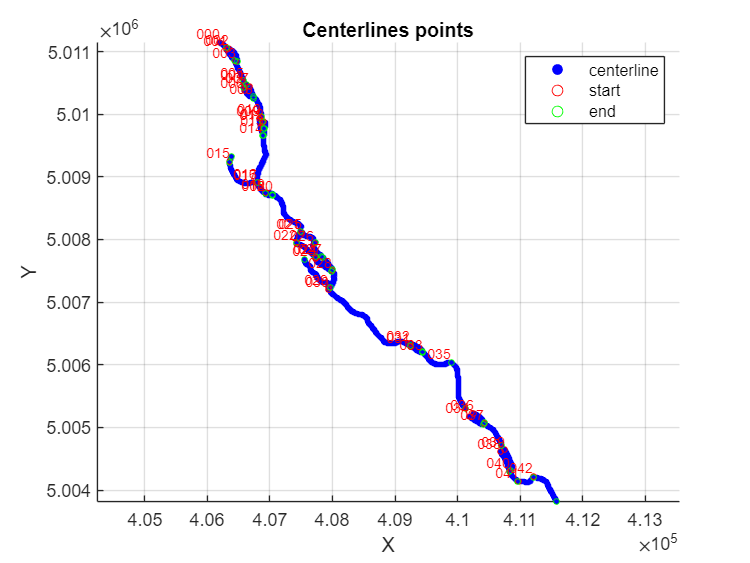

% Same plot to verify 
figure;
scatter(x_coords, y_coords, 10, 'b', 'filled');
title('Centerlines points');
xlabel('X');
ylabel('Y');
axis equal; 
grid on; 
hold on;
scatter(x_start, y_start, 10, 'or');
scatter(x_end, y_end, 10, 'og');
legend('centerline', 'start', 'end');

    mask_codes = strings(length(mask_files), 1); 

for i = 1:length(mask_files)
    [~, mask_name, ~] = fileparts(mask_files(i).name);
    mask_codes(i) = extractAfter(mask_name, 'I_'); 
end

if length(mask_codes) ~= length(x_start)
    error('Codes number is not equal to river segments!');
end

for i = 1:length(x_start)
    text(x_start(i), y_start(i), mask_codes(i), ...
    'FontSize', 8, 'Color', 'r', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
end
hold off;

% River segments number
num_sections = size(sections_ids, 1);

%% ADJACENCY MATRIX
adjacency_matrix = zeros(num_sections * 2 + 1);

all_ids = [sections_ids(:, 1); sections_ids(:, 2)]; % start and end IDs
adjacency_matrix(2:end, 1) = all_ids; 
adjacency_matrix(1, 2:end) = all_ids; 


% Loop to fill adjacency matrix 
distance_threshold = 51; 

for i = 1:num_sections
    start_coords = [x_start(i), y_start(i)]; % [x, y] start river segment i

    [~, mask_name_i, ~] = fileparts(mask_files(i).name);
    mask_code_i = extractAfter(mask_name_i, 'I_'); % Code of the river segment Es. '000'

    for j = 1:num_sections
            if i == j
            continue;
        end
        
        end_coords = [x_end(j), y_end(j)]; % [x, y] end of river segment j
        dist = sqrt(sum((start_coords - end_coords).^2)); % Euclidean distance

        if dist < distance_threshold
            [~, mask_name_j, ~] = fileparts(mask_files(j).name);
            mask_code_j = extractAfter(mask_name_j, 'I_'); % Es. '0001'
            
%             % Print
%             fprintf('The river segment _%s is before _%s\n', mask_code_j, mask_code_i);
            
            % Find corrisponding IDs in the adjacency matrix
            row_i = find(adjacency_matrix(2:end, 1) == sections_ids(j, 2)) + 1; % Row of the ending point j
            col_j = find(adjacency_matrix(1, 2:end) == sections_ids(i, 1)) + 1; % Column of the starting point i

            % Update adjacency matrix
            adjacency_matrix(row_i, col_j) = 1;  % The ending point j is close to the starting point i
            adjacency_matrix(col_j, row_i) = -1; % The starting point i is close to the ending point j
        end
    end
end

% % Show adjacency matrix
% disp('Adjacency Matrix:');
% disp(adjacency_matrix)

% Cell array initialization to store bif and conf details
bif_info = {};  % Each row: {SectionID, [Downstream IDs]}
conf_info = {}; % Each row: {SectionID, [Upstream IDs]}
bif_info_tratti = {};   % {SegmentCode, [Downstream SegmentCodes]}
conf_info_tratti = {};  % {SegmentCode, [Upstream SegmentCodes]}

num_ids = size(adjacency_matrix, 1) - 1; % exclude row and column title

% Column analysis (from 2nd to last)
for col = 2:(num_ids+1)
    
    sectionID = adjacency_matrix(1, col); % section ID
    
    % Find 1
    % SectionID gets from more than one section --> confluence
    contributorIndices = find(adjacency_matrix(2:end, col) == 1);
    if length(contributorIndices) > 1
        contributorIDs = adjacency_matrix(contributorIndices + 1, 1);
        conf_info{end+1, 1} = sectionID;
        conf_info{end, 2} = contributorIDs;
        % Find river segments codes
        code_current = all_centerlines(all_centerlines(:,1) == sectionID, 6);
        code_contributors = zeros(length(contributorIDs), 1);
        for k = 1:length(contributorIDs)
            idx = find(all_centerlines(:,1) == contributorIDs(k), 1);
            code_contributors(k) = all_centerlines(idx, 6);
        end
        conf_info_tratti{end+1, 1} = code_current;
        conf_info_tratti{end, 2} = code_contributors;
    end
    
    % Find -1
    % SectionID feeds more than one section --> bifurcation
    feederIndices = find(adjacency_matrix(2:end, col) == -1); % rows that this section flows into
    if length(feederIndices) > 1
        feederIDs = adjacency_matrix(feederIndices + 1, 1);
        bif_info{end+1, 1} = sectionID;
        bif_info{end, 2} = feederIDs;
        % Find river segments codes
        code_current = all_centerlines(all_centerlines(:,1) == sectionID, 6);
        code_feeders = zeros(length(feederIDs), 1);
        for k = 1:length(feederIDs)
            idx = find(all_centerlines(:,1) == feederIDs(k), 1);
            code_feeders(k) = all_centerlines(idx, 6);
        end
        bif_info_tratti{end+1, 1} = code_current;
        bif_info_tratti{end, 2} = code_feeders;
    end
end

%% Overcome bridges issue-manually insert bifurcation and confluences not found
% Bifurcations to force: 35 34 36; 37 38 39
% No confluences to force
while true
    prompt = 'Are there other bifurcations? (yes/no): ';
    str = lower(strtrim(input(prompt, 's')));
    if strcmp(str, 'no')
        break;
    elseif strcmp(str, 'yes')
        bif_input = input('Write river segments codes spaced (bifurcating_branch branch1 branch2): ', 's');
        tokens = strsplit(bif_input);
        if length(tokens) ~= 3
            warning('Invalid input. You must specify exactly 3 codes.');
            continue;
        end
        % Parse segment codes
        main_code = str2double(tokens{1});
        branch1_code = str2double(tokens{2});
        branch2_code = str2double(tokens{3});

        % Add river segments codes to bif_info_tratti
        bif_info_tratti(end+1, :) = {main_code, [branch1_code, branch2_code]};

        % Get end ID of the bifurcation and start IDs of the two branches
        main_idx = find(all_centerlines(:, 6) == main_code);
        b1_idx = find(all_centerlines(:, 6) == branch1_code);
        b2_idx = find(all_centerlines(:, 6) == branch2_code);

        if isempty(main_idx) || isempty(b1_idx) || isempty(b2_idx)
            warning('Could not find all river segments in all_centerlines.');
            continue;
        end

        main_last_id = all_centerlines(main_idx(end), 1);
        b1_first_id = all_centerlines(b1_idx(1), 1);
        b2_first_id = all_centerlines(b2_idx(1), 1);

        % Add points IDs to bif_info
        bif_info(end+1, :) = {main_last_id, [b1_first_id, b2_first_id]};
    else
        disp('Please answer with "yes" or "no".');
    end
end

while true
    prompt = 'Are there other confluences? (yes/no): ';
    str = lower(strtrim(input(prompt, 's')));
    if strcmp(str, 'no')
        break;
    elseif strcmp(str, 'yes')
        conf_input = input('Write river segments codes spaced (branch1 branch2 merging_branch): ', 's');
        tokens = strsplit(conf_input);
        if length(tokens) ~= 3
            warning('Invalid input. You must specify exactly 3 codes.');
            continue;
        end
        % Parse segment codes
        branch1_code = str2double(tokens{1});
        branch2_code = str2double(tokens{2});
        merging_code = str2double(tokens{3});

        % Add river segments codes to conf_info_tratti
        conf_info_tratti(end+1, :) = {merging_code, [branch1_code, branch2_code]};

        % Get end IDs of the two branches and start ID of the confluence
        b1_idx = find(all_centerlines(:, 6) == branch1_code);
        b2_idx = find(all_centerlines(:, 6) == branch2_code);
        merge_idx = find(all_centerlines(:, 6) == merging_code);

        if isempty(b1_idx) || isempty(b2_idx) || isempty(merge_idx)
            warning('Could not find all river segments in all_centerlines.');
            continue;
        end

        b1_last_id = all_centerlines(b1_idx(end), 1);
        b2_last_id = all_centerlines(b2_idx(end), 1);
        merge_first_id = all_centerlines(merge_idx(1), 1);

        % Add points IDs to conf_info
        conf_info(end+1, :) = {merge_first_id, [b1_last_id, b2_last_id]};
    else
        disp('Please answer with "yes" or "no".');
    end
end

%% ============================================================
%% TOPOLOGICAL ORDERING (fix for discharge propagation)
%% ============================================================
n_points = size(all_centerlines, 1);
section_to_index = containers.Map(all_centerlines(:,1), 1:n_points);
num_sections = size(sections_ids, 1);
start_ids = sections_ids(:,1);
end_ids   = sections_ids(:,2);

predecessor = cell(num_sections, 1);   % ID di monte per ciascun tronco (1 o 2 per confluenza)
edges = [];                            % archi [tronco_monte, tronco_valle] per il grafo

for s = 1:num_sections
    start_id = start_ids(s);

    % 1) Il tronco nasce da una CONFLUENZA?
    conf_match = find(cellfun(@(x) isequal(x, start_id), conf_info(:,1)));
    if ~isempty(conf_match)
        up_ids = conf_info{conf_match, 2};
        for k = 1:numel(up_ids)
            s_up = find(end_ids == up_ids(k));
            if isempty(s_up)
                error('Topologia: tronco a monte non trovato per confluenza (ID %d).', up_ids(k));
            end
            predecessor{s} = [predecessor{s}, s_up];
            edges = [edges; s_up, s];
        end
        continue
    end

    % 2) Il tronco è un ramo di BIFORCAZIONE?
    is_branch = false;
    for b = 1:size(bif_info,1)
        if any(bif_info{b,2} == start_id)
            s_up = find(end_ids == bif_info{b,1});
            if isempty(s_up)
                error('Topologia: tronco a monte non trovato per biforcazione (ID %d).', bif_info{b,1});
            end
            predecessor{s} = s_up;
            edges = [edges; s_up, s];
            is_branch = true;
            break
        end
    end
    if is_branch, continue, end

    % 3) Continuazione semplice: unica connessione nella adjacency_matrix
    col = find(adjacency_matrix(1,2:end) == start_id) + 1;
    if ~isempty(col)
        row = find(adjacency_matrix(2:end, col) == 1);
        if numel(row) == 1
            up_id = adjacency_matrix(row+1, 1);
            s_up = find(end_ids == up_id);
            if isempty(s_up)
                error('Topologia: tronco a monte non trovato per continuazione semplice (ID %d).', up_id);
            end
            predecessor{s} = s_up;
            edges = [edges; s_up, s];
            continue
        elseif numel(row) > 1
            error('Topologia: il tronco %d ha più connessioni a monte non registrate come confluenza.', s);
        end
    end

    % 4) Nessuna connessione trovata -> testata di rete
    predecessor{s} = [];
end

% Ordinamento topologico
if isempty(edges)
    topo_order = 1:num_sections;
else
    G = digraph(edges(:,1), edges(:,2), [], num_sections);
    try
        topo_order = toposort(G);
    catch ME
        error('Il grafo dei tronchi contiene un ciclo: verificare bif_info/conf_info. %s', ME.message);
    end
end

% --- Controllo diagnostico: confronto con l'assunzione "codice crescente = valle"
codes_by_section = arrayfun(@(s) all_centerlines(find(all_centerlines(:,1)==sections_ids(s,1),1), 6), 1:num_sections);
[~, order_by_code] = sort(codes_by_section);
if ~isequal(order_by_code(:), topo_order(:))
    % Confronto per RANGO (posizione), non per insieme: setdiff è inutile
    % qui perché i due ordinamenti contengono sempre gli stessi tronchi.
    rank_by_code = zeros(num_sections,1);
    rank_by_code(order_by_code) = 1:num_sections;
    rank_topo = zeros(num_sections,1);
    rank_topo(topo_order) = 1:num_sections;

    mismatched = find(rank_by_code ~= rank_topo);
    mismatch_codes = codes_by_section(mismatched);

    warning(['L''ordine per codice crescente NON coincide con l''ordine topologico reale. ' ...
             'Uso l''ordine geometrico (corretto). Codici tronco con posizione diversa: %s'], ...
             mat2str(mismatch_codes));
end


% --- Individuazione della/e testata/e di rete e assegnazione portata a monte
roots = find(cellfun(@isempty, predecessor));
if isempty(roots)
    error('Topologia: nessuna testata di rete individuata (possibile ciclo o errore nei dati).');
end
if numel(roots) > 1
    warning(['Trovate %d testate di rete senza tronco a monte: %s. ' ...
             'Verificare quale corrisponde alla stazione di monte (San Benigno) e se le altre ' ...
             'sono affluenti che richiedono una portata nota da assegnare manualmente.'], ...
             numel(roots), mat2str(roots));
    root_codes = codes_by_section(roots);
    disp(table(roots(:), root_codes(:), 'VariableNames', {'row_index','tronco_code'}));
end
network_root = roots(1); 

% Clean anomalous single values
tronchi_uniq = unique(all_centerlines(:,6));
outlier_flags = false(height(all_centerlines), 1);
for t = tronchi_uniq'
    idx = find(all_centerlines(:,6) == t);
    z = all_centerlines(idx, 4);
    if numel(z) < 5, continue; end
    curvatura = [0; diff(diff(z)); 0];
    soglia = max(1.0, 3 * mad(curvatura, 1) / 0.6745);
    out = abs(curvatura) > soglia;
    outlier_flags(idx(out)) = true;
end
fprintf('%d punti con probabile glitch isolato di z_coords\n', nnz(outlier_flags));

144 punti con probabile glitch isolato di z_coords


disp(all_centerlines(outlier_flags, [1 4 6]))

   1.0e+03 *

    0.0540    0.2597    0.0020
    0.0550    0.2582    0.0020
    0.0560    0.2597    0.0020
    0.0570    0.2582    0.0020
    0.0580    0.2596    0.0020
    0.0620    0.2595    0.0020
    0.1690    0.2547    0.0080
    0.1700    0.2541    0.0080
    0.1710    0.2552    0.0080
    0.1720    0.2547    0.0080
    0.2290    0.2523    0.0090
    0.2300    0.2532    0.0090
    0.2310    0.2522    0.0090
    0.2590    0.2518    0.0120
    0.2600    0.2537    0.0120
    0.2610    0.2463    0.0120
    0.2620    0.2536    0.0120
    0.2630    0.2511    0.0120
    0.2640    0.2536    0.0120
    0.3970    0.2512    0.0160
    0.3980    0.2497    0.0160
    0.3990    0.2512    0.0160
    0.4000    0.2493    0.0160
    0.4010    0.2513    0.0160
    0.4020    0.2495    0.0160
    0.4030    0.2513    0.0160
    0.4040    0.2501    0.0160
    0.4050    0.2514    0.0160
    0.4920    0.2457    0.0190
    0.4930    0.2493    0.0190
    0.4940    0.2453    0.0190
    0.5120    0.2488    0


z_original = all_centerlines(:,4);   % snapshot pre-correzione, per non propagare errori tra correzioni vicine
for row = find(outlier_flags)'
    idx = find(all_centerlines(:,6) == all_centerlines(row,6));
    pos_in_tronco = find(idx == row);
    if pos_in_tronco > 1 && pos_in_tronco < numel(idx)
        z_prev = z_original(idx(pos_in_tronco-1));
        z_next = z_original(idx(pos_in_tronco+1));
        all_centerlines(row, 4) = mean([z_prev, z_next]);
    end
end 
%% Smoothing mirato per tronchi con oscillazione sistematica
% (non presa dal rilevatore di glitch isolati sopra, perché il rumore qui
% è distribuito su più punti consecutivi, non un singolo outlier).
% Finestra ampia, 7, per sopprimere oscillazione quasi periodica
tronchi_da_smussare = struct('tronco', {12, 19, 26, 30, 38, 39, 32}, ...
                              'window', {7,  7,  7,  7,  7,  7,  9});

for k = 1:numel(tronchi_da_smussare)
    t = tronchi_da_smussare(k).tronco;
    w = tronchi_da_smussare(k).window;
    idx_t = find(all_centerlines(:,6) == t);
    if numel(idx_t) < w, continue; end

    z_before = all_centerlines(idx_t, 4);
    z_after  = movmedian(z_before, w);

    fprintf('Tronco %d (w=%d): ampiezza prima = %.2f m, dopo = %.2f m\n', ...
        t, w, max(z_before)-min(z_before), max(z_after)-min(z_after));

    all_centerlines(idx_t, 4) = z_after;
end

Tronco 12 (w=7): ampiezza prima = 5.98 m, dopo = 0.87 m
Tronco 19 (w=7): ampiezza prima = 4.71 m, dopo = 1.09 m
Tronco 26 (w=7): ampiezza prima = 3.63 m, dopo = 0.65 m
Tronco 30 (w=7): ampiezza prima = 5.67 m, dopo = 5.59 m
Tronco 38 (w=7): ampiezza prima = 3.70 m, dopo = 1.25 m
Tronco 39 (w=7): ampiezza prima = 4.15 m, dopo = 2.08 m
Tronco 32 (w=9): ampiezza prima = 4.74 m, dopo = 1.28 m


z_coords = all_centerlines(:, 4);
% Ri-sincronizza z_coords con all_centerlines(:,4) dopo la pulizia dei glitch,
% altrimenti pendenze e calcolo idraulico restano legati alla versione non pulita
z_coords = all_centerlines(:, 4);

%% Slope calculation (mean of segment-by-segment slopes)
slope_sect = zeros(size(all_centerlines, 1), 1); 
n_sections = size(sections_ids_with_coords, 1);

for s = 1:n_sections
    idx_start = sections_ids_with_coords(s, 1);
    idx_end   = sections_ids_with_coords(s, 5);

    if (idx_end - idx_start + 1) >= 2 % If the river segment has more than 2 points
        % Extract centerline points in that river segment
        x = all_centerlines(idx_start:idx_end, 2);
        y = all_centerlines(idx_start:idx_end, 3);
        z = all_centerlines(idx_start:idx_end, 4); 

        % Calculate differences among consecutive points
        dz = diff(z);
        dx = diff(x);
        dy = diff(y);
        ds = sqrt(dx.^2 + dy.^2); % Euclidean distance
        ss=zeros(1,numel(ds)+1);
        for j=2:numel(ds)+1
            ss(j)=ss(j-1)+ds(j-1);
        end
        
        p=polyfit(ss,z.',1);
        slope_sect(idx_start:idx_end) =max(1.6e-4,atan(-p(1)));
          

    else
        warning("Riversegment %d is too short. Defined slope assigned", s);
        slope_sect(idx_start:idx_end) = 1.6e-4;
    end
end

sect_slope = slope_sect(:);

g = 9.81;               
n_manning = 0.03;       % Manning's coefficient
% LiDAR flight 17/03/2025 
Q_upstream = 10.8;        % Discharge SAN BENIGNO ORCO [m^3/s]
level_upstream = 0.695;     % Water level SAN BENIGNO ORCO [m] from most recent (2023) rating curve
% n_points = length(x_coords);
% section_to_index = containers.Map(all_centerlines(:,1), 1:n_points);
h_rect_all = NaN(n_points,1); % Depth 
z_rect_all = NaN(n_points,1); % riverbed elevation matrix
sectionWet(1:n_points) = struct('h', NaN, 'quot', NaN, 'Q', NaN); % structure
Q_map = NaN(n_points, 1);       % Discharge preallocation for each section
% Q_map(1) = Q_upstream;          % Discharge for the first section
root_start_id = sections_ids(network_root, 1);
Q_map(section_to_index(root_start_id)) = Q_upstream;
%% For cycle for all sections 
row_idx_cell = arrayfun(@(s) find(all_centerlines(:,1) >= sections_ids(s,1) & ...
                     all_centerlines(:,1) <= sections_ids(s,2)), topo_order, 'UniformOutput', false);
iter_rows = vertcat(row_idx_cell{:});
is_segment_start = ismember(all_centerlines(:,1), sections_ids(:,1));

for k = 1:n_points
    i = iter_rows(k);
    % ----------------------------- BIFURCATION -----------------------------
    if ismember(all_centerlines(i,1), cell2mat(bif_info(:,1))) % If bifurcation
        width = widths_all(i);    
        slope = sect_slope(i);
        Q_map(i) = Q_map(i-1);
        h_rect = (Q_map(i) / (width * (1/n_manning) * sqrt(slope)))^(3/5);
        z_rect = z_coords(i) - h_rect;
        sectionWet(i).h = h_rect;
        sectionWet(i).quot = z_rect;
        sectionWet(i).Q = Q_map(i);
        h_rect_all(i) = h_rect;
        z_rect_all(i) = z_rect;

        % Find the two branches of the bifurcation
        bif_idx = find(cell2mat(bif_info(:,1)) == all_centerlines(i,1));
        next_sections = bif_info{bif_idx, 2};
   
            if length(next_sections) == 2
                sec1 = next_sections(1);
                sec2 = next_sections(2);
    
                % Bifurcation branches indexes
                idx1 = section_to_index(sec1);
                idx2 = section_to_index(sec2);
                % (if sect1 is the 5th ID in all_centerlines(:,1) follows idx1=5)
                
                width1 = widths_all(idx1);
                width2 = widths_all(idx2);
                slope1 = sect_slope(idx1);
                slope2 = sect_slope(idx2);
    
                % System of eq: [Q1, Q2, h1, h2]
                F = @(x) [
                    % 1. Discharge conservation
                    x(1) + x(2) - Q_map(i);
                    % 2. Chezy's eq 1
                    x(1) - (1/n_manning) * width1 * x(3)^(5/3) * sqrt(slope1);
                    % 3. Chezy's eq 2
                    x(2) - (1/n_manning) * width2 * x(4)^(5/3) * sqrt(slope2);
                    % 4. Bernoulli
                    x(3) + x(1)^2 / (2 * g * (width1 * x(3))^2) ...
                          - (x(4) + x(2)^2 / (2 * g * (width2 * x(4))^2));
                ];
    
                idx_current = section_to_index(all_centerlines(i,1));
                if ~all(isnan(h_rect_all(idx_current)))
                    h_init = [h_rect_all(idx_current); h_rect_all(idx_current)];
                else
                    h_init = [level_upstream; level_upstream];
                end
    
                x0 = [Q_map(i)/2; Q_map(i)/2; h_init(1); h_init(2)];
    
                options = optimoptions('fsolve', 'Display', 'iter', 'FunctionTolerance', 1e-8);
%                 disp(['Current section: ', num2str(all_centerlines(i,1))]);
%                 disp(['x0 = ', num2str(x0')]);
%                 disp(['width1 = ', num2str(width1), ', width2 = ', num2str(width2)]);
%                 disp(['slope1 = ', num2str(slope1), ', slope2 = ', num2str(slope2)]);

                [x_sol, fval, exitflag] = fsolve(F, x0, options);
                  
                if exitflag > 0 && all(isreal(x_sol)) && all(x_sol > 0)
                    Q1 = x_sol(1); Q2 = x_sol(2);
                    h_rect1 = x_sol(3); h_rect2 = x_sol(4);
                else
                    warning('No physical solution for bifurcation in section %d', all_centerlines(i,1));
                    disp('------ BIFURCATION FAILURE INFO ------');
                    disp(['Section ID: ', num2str(all_centerlines(i,1))]);
                    disp(['Widths: ', num2str([width1, width2])]);
                    disp(['Slopes: ', num2str([slope1, slope2])]);
                    disp(['Initial guess: ', num2str(x0')]);
                    disp(['Solution: ', num2str(x_sol')]);
                    disp(['fval: ', num2str(fval')]);
                    % Fallback:one of the two branches is almost flat
                    Q1 = Q_map(i) * width1 / (width1 + width2);
                    Q2 = Q_map(i) - Q1;
        
                    h_rect1 = (Q1 / (width1 * (1/n_manning) * sqrt(slope1)))^(3/5);
                    h_rect2 = (Q2 / (width2 * (1/n_manning) * sqrt(slope2)))^(3/5);
                end
                % Save
                    Q_map(idx1) = Q1;
                    Q_map(idx2) = Q2;
                    z_rect1 = z_coords(idx1) - h_rect1;
                    z_rect2 = z_coords(idx2) - h_rect2;
                    
                    sectionWet(idx1).h = h_rect1;
                    sectionWet(idx1).quot = z_rect1;
                    sectionWet(idx1).Q = Q1;
                    sectionWet(idx2).h = h_rect2;
                    sectionWet(idx2).quot = z_rect2;
                    sectionWet(idx2).Q = Q2;
                    h_rect_all(idx1) = h_rect1;
                    h_rect_all(idx2) = h_rect2;
                    z_rect_all(idx1) = z_rect1;
                    z_rect_all(idx2) = z_rect2;
            end
    % ----------------------------- CONFLUENCE -----------------------------  
    elseif ismember(all_centerlines(i,1), cell2mat(conf_info(:,1))) % If confluence
        width = widths_all(i);
        slope = sect_slope(i);
    
        conf_idx = find(cell2mat(conf_info(:,1)) == all_centerlines(i,1));
        upstream_sections = conf_info{conf_idx, 2};
    
        idx1 = section_to_index(upstream_sections(1));
        idx2 = section_to_index(upstream_sections(2));
    
        Q1 = Q_map(idx1);
        Q2 = Q_map(idx2);
        Q_total = Q1 + Q2;
        Q_map(i) = Q_total;
        h_rect = (Q_total / (width * (1/n_manning) * sqrt(slope)))^(3/5);
        z_rect = z_coords(i) - h_rect;
        sectionWet(i).h = h_rect;
        sectionWet(i).quot = z_rect;
        sectionWet(i).Q = Q_total;
        h_rect_all(i) = h_rect;
        z_rect_all(i) = z_rect;
        if i < n_points && ...
           ~ismember(all_centerlines(i+1,1), cell2mat(conf_info(:,1))) && ...
           ~ismember(all_centerlines(i+1,1), cell2mat(bif_info(:,1)))
            Q_map(i+1) = Q_total;
        end
    else
% ----------------------------- SINGLE CHANNEL -----------------------------
        width = widths_all(i);
        slope = sect_slope(i);
        if isnan(width) || width <= 0 || isnan(slope) || slope <= 0
           warning('Invalid width or slope at section %d', i);
           continue;
        end
        if isnan(Q_map(i))
            if is_segment_start(i)
                seg_idx = find(sections_ids(:,1) == all_centerlines(i,1));
                up = predecessor{seg_idx};
                if isempty(up)
                    warning('Tronco %d (testata di rete): portata a monte non definita. Sezione saltata.', seg_idx);
                    continue
                end
                up_row = section_to_index(sections_ids(up,2));
                if isnan(Q_map(up_row))
                    error('Tronco %d: portata del tronco a monte (%d) non ancora calcolata. Errore di ordine topologico.', seg_idx, up);
                end
                Q_map(i) = Q_map(up_row);
            elseif k > 1
                Q_map(i) = Q_map(iter_rows(k-1));   % continuazione interna allo stesso tronco
            else
                warning('Q_map(%d) non definita e non è possibile risalire al valore precedente.', i);
                continue;
            end
        end

        Q_local = Q_map(i);
        h_rect = (Q_local / (width * (1/n_manning) * sqrt(slope)))^(3/5);
        z_rect = z_coords(i) - h_rect;
        sectionWet(i).h = h_rect;
        sectionWet(i).quot = z_rect;
        sectionWet(i).Q = Q_local;
        h_rect_all(i) = h_rect;
        z_rect_all(i) = z_rect;
        % Discharge propagation
        if i < n_points && ...
           ~ismember(all_centerlines(i+1,1), cell2mat(conf_info(:,1))) && ...
           ~ismember(all_centerlines(i+1,1), cell2mat(bif_info(:,1)))
        
           Q_map(i+1) = Q_local;
        end
    end
end


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          5         3696.94                      3.81e+03               1
     1         10         182.442              1            457               1
     2         15         4.37732        1.66784           54.2             2.5
     3         20      0.00577539        0.96403           1.54            4.17
     4         25     2.42676e-07      0.0659429         0.0121            4.17
     5         30     2.68712e-17    0.000219119       1.26e-07            4.17

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

addpath('\\nas-camporeale\home\ELISA\BATHIMETRY\0_MODIFICHE');
addpath('\\nas-camporeale\home\ELISA\BATHIMETRY\2025_bat');
% Save centerline with corrected bathymetry in CSV format
fileID = fopen('\\nas-camporeale\home\ELISA\BATHIMETRY\0_MODIFICHE\0_centerline_bat_rect_2025_modifiche_3.csv', 'w');

fprintf(fileID, 'X,Y,Z\n');

for i = 1:length(x_coords)
    fprintf(fileID, '%.3f,%.3f,%.3f\n', x_coords(i), y_coords(i), z_rect_all(i));
end

fclose(fileID);
% Save depth for each cross-section
save('h_rect_all_modifiche_3.mat', 'h_rect_all');
% Create a bathymetry corrected matrix like z_matrix 
z_rect_all_matrix = NaN(size(z_matrix));  

for i = 1:size(z_matrix, 1)
    mask = ~isnan(z_matrix(i, :)); 
    z_rect_all_matrix(i, mask) = z_rect_all(i);
end
% Save river bottom elevation for each cross-section
save('z_rect_all_modifiche_3.mat', 'z_rect_all');

[mask_wetarea, Rmask_wetarea] = readgeoraster('I_wetarea_2025.tif');
mask_wetarea = logical(mask_wetarea);
% whos name_variable to get info
% imagesc to visualize
% % Read dtm as raster
[raster_dtm, R_dtm] = readgeoraster('cutDTM_50cm_ORCO_UTM32N_ETRF2000.tif');
raster_dtm = double(raster_dtm);
raster_dtm(raster_dtm == -32767) = NaN;
% Are R_dtm and Rmask_wetarea aligned?
isequal(R_dtm, Rmask_wetarea)

ans = logical
   0


fprintf('--- DTM ---\n');

--- DTM ---


disp(R_dtm)

  MapPostingsReference with properties:

             XWorldLimits: [406104.75 412013.25]
             YWorldLimits: [5003720.25 5011211.25]
               RasterSize: [14983 11818]
     RasterInterpretation: 'postings'
         ColumnsStartFrom: 'north'
            RowsStartFrom: 'west'
    SampleSpacingInWorldX: 1/2
    SampleSpacingInWorldY: 1/2
     RasterExtentInWorldX: 5908.5
     RasterExtentInWorldY: 7491
         XIntrinsicLimits: [1 11818]
         YIntrinsicLimits: [1 14983]
       TransformationType: 'rectilinear'
     CoordinateSystemType: 'planar'
             ProjectedCRS: [1×1 projcrs]





fprintf('--- Wet Area Mask ---\n');

--- Wet Area Mask ---


disp(Rmask_wetarea)

  MapCellsReference with properties:

            XWorldLimits: [406123 412777]
            YWorldLimits: [5003370 5011486]
              RasterSize: [16232 13308]
    RasterInterpretation: 'cells'
        ColumnsStartFrom: 'north'
           RowsStartFrom: 'west'
      CellExtentInWorldX: 1/2
      CellExtentInWorldY: 1/2
    RasterExtentInWorldX: 6654
    RasterExtentInWorldY: 8116
        XIntrinsicLimits: [0.5 13308.5]
        YIntrinsicLimits: [0.5 16232.5]
      TransformationType: 'rectilinear'
    CoordinateSystemType: 'planar'
            ProjectedCRS: [1×1 projcrs]




% DTM bounding box
xmin_dtm = R_dtm.XWorldLimits(1);
xmax_dtm = R_dtm.XWorldLimits(2);
ymin_dtm = R_dtm.YWorldLimits(1);
ymax_dtm = R_dtm.YWorldLimits(2);

% Maschera bounding box
xmin_mask = Rmask_wetarea.XWorldLimits(1);
xmax_mask = Rmask_wetarea.XWorldLimits(2);
ymin_mask = Rmask_wetarea.YWorldLimits(1);
ymax_mask = Rmask_wetarea.YWorldLimits(2);

fprintf('DTM extent: xmin=%.2f, xmax=%.2f, ymin=%.2f, ymax=%.2f\n', xmin_dtm, xmax_dtm, ymin_dtm, ymax_dtm);

DTM extent: xmin=406104.75, xmax=412013.25, ymin=5003720.25, ymax=5011211.25


fprintf('Mask extent: xmin=%.2f, xmax=%.2f, ymin=%.2f, ymax=%.2f\n', xmin_mask, xmax_mask, ymin_mask, ymax_mask);

Mask extent: xmin=406123.00, xmax=412777.00, ymin=5003370.00, ymax=5011486.00


% Coordinate del primo pixel TRUE della maschera (in coordinate mondo)
% Crea una griglia di coordinate mondo per la maschera
[cols_mask, rows_mask] = meshgrid(1:size(mask_wetarea,2), 1:size(mask_wetarea,1));
[xw_mask, yw_mask] = Rmask_wetarea.intrinsicToWorld(cols_mask, rows_mask);

% Tieni solo i pixel TRUE della maschera
mask_true_idx = find(mask_wetarea);
x_mask_true = xw_mask(mask_true_idx);
y_mask_true = yw_mask(mask_true_idx);

% Converti le coordinate mondo della maschera in indici intrinseci del DTM
[col_in_dtm, row_in_dtm] = R_dtm.worldToIntrinsic(x_mask_true, y_mask_true);

% Arrotonda agli indici interi
col_in_dtm = round(col_in_dtm);
row_in_dtm = round(row_in_dtm);

% Filtra indici fuori dai limiti del DTM
valid = col_in_dtm >= 1 & col_in_dtm <= size(raster_dtm,2) & ...
        row_in_dtm >= 1 & row_in_dtm <= size(raster_dtm,1);

col_in_dtm = col_in_dtm(valid);
row_in_dtm = row_in_dtm(valid);

% Costruisci mask_extended usando indici lineari
mask_extended = false(size(raster_dtm));
lin_idx = sub2ind(size(raster_dtm), row_in_dtm, col_in_dtm);
mask_extended(lin_idx) = true;

% Verifica: campiona alcuni punti TRUE e controlla che le coordinate coincidano
sample_idx = mask_true_idx(1:100:end);  % ogni 100 pixel veri
x_check = xw_mask(sample_idx);
y_check = yw_mask(sample_idx);

[col_check, row_check] = R_dtm.worldToIntrinsic(x_check, y_check);
[x_back, y_back] = R_dtm.intrinsicToWorld(round(col_check), round(row_check));

max_err_x = max(abs(x_check - x_back));
max_err_y = max(abs(y_check - y_back));
fprintf('Max roundtrip error: X=%.4f m, Y=%.4f m\n', max_err_x, max_err_y);

Max roundtrip error: X=0.0000 m, Y=0.0000 m


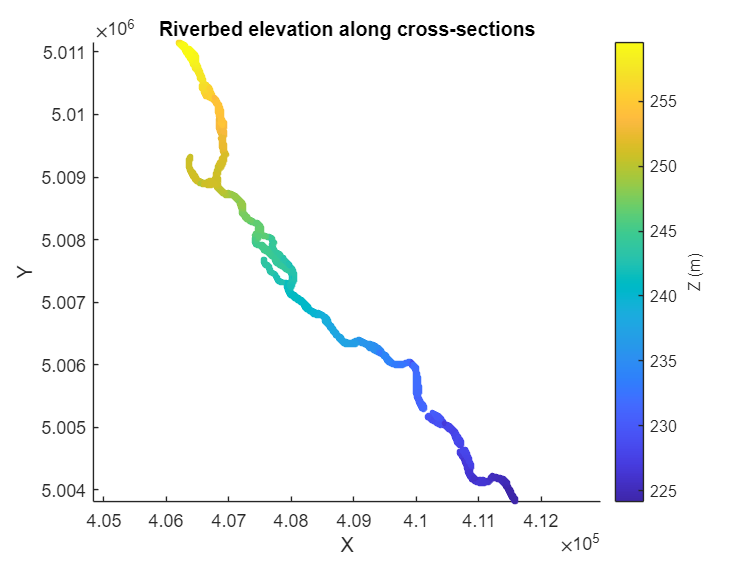

% Extract valid points (not NaN) and plot riverbed elevation
mask_valid = ~isnan(z_rect_all_matrix);
x = x_matrix(mask_valid);
y = y_matrix(mask_valid);
z = z_rect_all_matrix(mask_valid);
figure;
scatter(x, y, 10, z, 'filled');
clim_riverbed = prctile(z, [1 99]);   % percentili invece di min e max puri, robusto a residui outlier isolati
caxis(clim_riverbed);
ylabel(colorbar, 'Z (m)');
xlabel('X'); ylabel('Y');
title('Riverbed elevation along cross-sections');
axis equal;

% Create Interpolant
F = scatteredInterpolant(x, y, z, 'natural', 'none');


% Create interpolation grid 
[cols, rows] = meshgrid(1:size(raster_dtm,2), 1:size(raster_dtm,1));
[xq, yq] = R_dtm.intrinsicToWorld(cols, rows);  % Spatial coordinates
zq = F(xq, yq);  % Interpolation over the grid

% Correction 
raster_dtm_corrected = raster_dtm;

% Non alzare mai il fondo sopra la quota LiDAR originale: il modello deve
% solo aggiungere informazione batimetrica (approfondire), mai sovrascrivere
% verso l'alto quota che il LiDAR ha già misurato correttamente.
n_would_raise = nnz(mask_extended & (zq > raster_dtm));
% fprintf('Pixel dove la correzione alzerebbe il fondo sopra il DTM originale: %d (%.2f%% area corretta)\n', ...
%     n_would_raise, 100*n_would_raise/nnz(mask_extended));

zq_safe = min(zq, raster_dtm);
raster_dtm_corrected(mask_extended) = zq_safe(mask_extended);

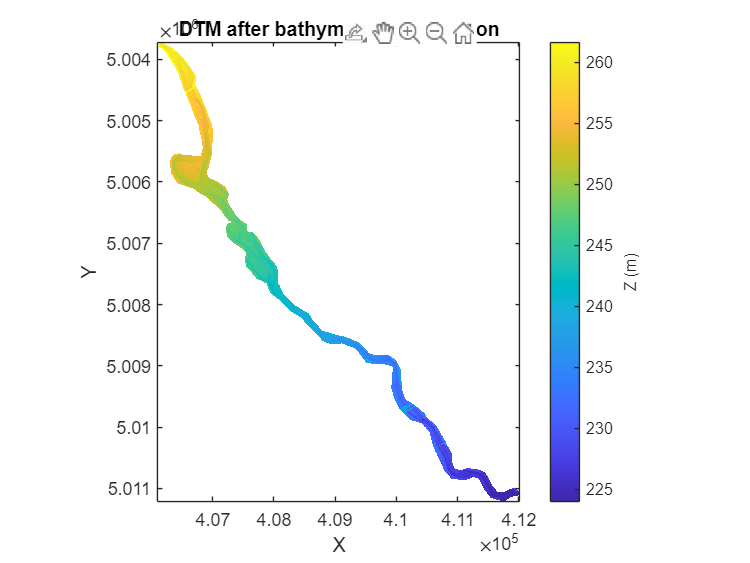

figure;
imAlpha = true(size(raster_dtm_corrected));
imAlpha(raster_dtm_corrected == 0 | isnan(raster_dtm_corrected)) = false;
imagesc(R_dtm.XWorldLimits, R_dtm.YWorldLimits, raster_dtm_corrected, 'AlphaData', imAlpha);
axis image;
colormap(parula);
valid_vals = raster_dtm_corrected(~isnan(raster_dtm_corrected));
caxis(prctile(valid_vals, [1 99]));
cb = colorbar;
ylabel(cb, 'Z (m)');
xlabel('X'); ylabel('Y');
title('DTM after bathymentric correction');

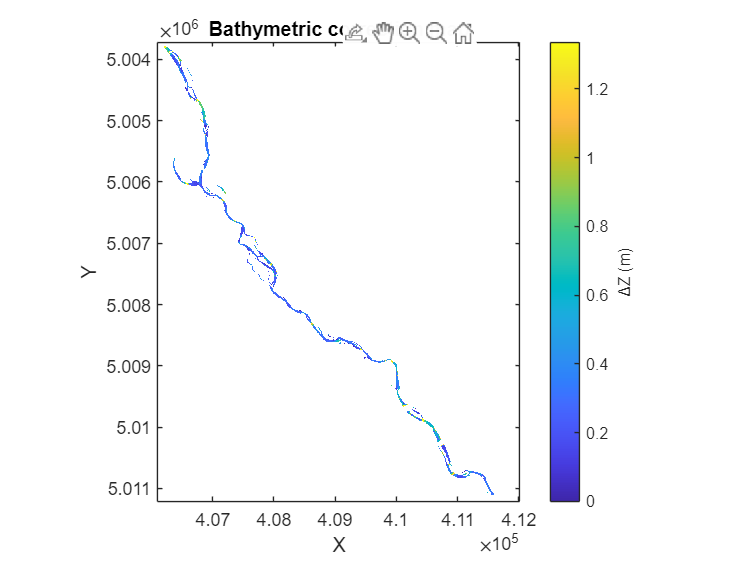

%% Bathymetric correction map - DoD
DoD = raster_dtm - raster_dtm_corrected;

figure;
imAlpha = true(size(DoD));
imAlpha(DoD == 0 | isnan(DoD)) = false;   % trasparente dove non è stata applicata alcuna correzione

imagesc(R_dtm.XWorldLimits, R_dtm.YWorldLimits, DoD, 'AlphaData', imAlpha);
set(gca, 'Color', 'white');           % sfondo bianco sotto le parti trasparenti
axis image;
colormap(parula);
nz = DoD(DoD > 0 & ~isnan(DoD));
L = prctile(nz, 98);      % dinamico, robusto a residui pixel estremi
caxis([0 L]);
cb = colorbar;
ylabel(cb, 'ΔZ (m)');
title('Bathymetric correction map');
xlabel('X'); ylabel('Y');


% % Save & plot
geotiffwrite('\\nas-camporeale\home\ELISA\BATHIMETRY\0_MODIFICHE\0_DTM_bat_corrected_2025_modifiche_5.tif', raster_dtm_corrected, R_dtm, 'CoordRefSysCode', 32632);
geotiffwrite('\\nas-camporeale\home\ELISA\BATHIMETRY\0_MODIFICHE\0_DoD_bat_corrected_2025_modifiche_5.tif', DoD, R_dtm, 'CoordRefSysCode', 32632);
disp('Done!');

Done!


%% Checking
is_bif_conf = ismember(all_centerlines(:,1), cell2mat(bif_info(:,1))) | ismember(all_centerlines(:,1), cell2mat(conf_info(:,1)));
z_coords_check = all_centerlines(:,4);
residuo_formula = z_rect_all - (z_coords_check - h_rect_all);
inconsistenti = find(abs(residuo_formula) > 0.01 & ~is_bif_conf);
fprintf('%d punti (canale singolo) dove z_rect NON è coerente con z_coords - h_rect\n', numel(inconsistenti));

0 punti (canale singolo) dove z_rect NON è coerente con z_coords - h_rect


if ~isempty(inconsistenti)
    disp(all_centerlines(inconsistenti(1:min(10,end)), [1 6]))
end

% outlier_flags è la variabile prodotta dal blocco "clean anomalous single values"
righe_pulite = find(outlier_flags);
righe_inconsistenti = inconsistenti;  % dal controllo di coerenza precedente

fprintf('Righe pulite dal blocco anomalie: %d\n', numel(righe_pulite));

Righe pulite dal blocco anomalie: 175


fprintf('Righe inconsistenti trovate ora: %d\n', numel(righe_inconsistenti));

Righe inconsistenti trovate ora: 0


fprintf('Sovrapposizione: %d\n', numel(intersect(righe_pulite, righe_inconsistenti)));

Sovrapposizione: 0


% La quota di fondo corretta deve scendere (o restare piatta) andando verso valle,
% con tolleranza per rumore locale — un salto in salita ampio e isolato è sospetto
for t = unique(all_centerlines(:,6))'
    idx = find(all_centerlines(:,6) == t);
    if numel(idx) < 3, continue; end
    dz = diff(z_rect_all(idx));
    n_risalite = nnz(dz > 1);   % soglia 1 m, adatta se troppo/poco sensibile
    if n_risalite > 0
        fprintf('Tronco %d: %d punti con risalita di fondo > 1 m rispetto al punto precedente\n', t, n_risalite);
    end
end

Tronco 2: 2 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 8: 1 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 12: 3 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 16: 4 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 19: 3 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 20: 5 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 25: 4 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 26: 3 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 27: 1 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 30: 6 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 32: 3 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 35: 3 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 36: 2 punti con risalita di fondo > 1 m rispetto al punto precedente
Tronco 37: 2 p

fprintf('%-8s %-12s %-16s\n', 'Tronco', 'N_risalite', 'Max_risalita_m');

Tronco   N_risalite   Max_risalita_m  


for t = unique(all_centerlines(:,6))'
    idx = find(all_centerlines(:,6) == t);
    if numel(idx) < 3, continue; end
    dz = diff(z_rect_all(idx));
    rises = dz(dz > 1);
    if ~isempty(rises)
        fprintf('%-8d %-12d %-16.2f\n', t, numel(rises), max(rises));
    end
end

2        2            1.42            
8        1            1.23            
12       3            7.40            
16       4            1.94            
19       3            3.89            
20       5            1.57            
25       4            1.36            
26       3            3.13            
27       1            1.11            
30       6            1.41            
32       3            4.25            
35       3            4.54            
36       2            1.39            
37       2            1.74            
38       6            3.20            
39       2            2.87            


% Anomalia tronco 12
idx = find(all_centerlines(:,6) == 12);
dz = diff(z_rect_all(idx));
[max_dz, k] = max(dz);
row_prev = idx(k); row_next = idx(k+1);

fprintf('Tronco 12: salto max = %.2f m tra ID %d e ID %d\n', max_dz, ...
    all_centerlines(row_prev,1), all_centerlines(row_next,1));

Tronco 12: salto max = 7.40 m tra ID 261 e ID 262



% Contesto: qualche sezione prima e dopo il salto
ctx = max(1,k-3):min(numel(idx),k+3);
T = table(all_centerlines(idx(ctx),1), widths_all(idx(ctx)), sect_slope(idx(ctx)), ...
    Q_map(idx(ctx)), h_rect_all(idx(ctx)), z_rect_all(idx(ctx)), ...
    ismember(all_centerlines(idx(ctx),1), cell2mat(bif_info(:,1))), ...
    ismember(all_centerlines(idx(ctx),1), cell2mat(conf_info(:,1))), ...
    'VariableNames', {'ID','width','slope','Q','h_rect','z_rect','e_bif','e_conf'});
disp(T)

    ID     width     slope        Q       h_rect     z_rect    e_bif    e_conf
    ___    _____    _______    _______    _______    ______    _____    ______

    258       9     0.00016    0.15643     0.1476    254.04    false    false 
    259     5.5     0.00016    0.15643    0.19834    251.64    false    false 
    260     4.5     0.00016    0.15643    0.22371    253.52    false    false 
    261       6     0.00016    0.15643    0.18825    246.06    false    false 
    262     9.5     0.00016    0.15643    0.14289    253.47    false    false 
    263       7     0.00016    0.15643    0.17162    250.89    false    false 
    264    11.5     0.00016    0.15643    0.12741    253.48    false    false 



tronchi_sospetti = [19 26 30 32 35 38 39];   % 12 già gestito sopra

fprintf('\n%-8s %-12s %-14s %-14s\n', 'Tronco', 'Salto_prima', 'Salto_w7', 'Esito');

Tronco   Salto_prima  Salto_w7       Esito         


for t = tronchi_sospetti
    idx_t = find(all_centerlines(:,6) == t);
    if numel(idx_t) < 7, continue; end

    z0 = all_centerlines(idx_t, 4);
    salto_prima = max(abs(diff(z0)));

    z_test = movmedian(z0, 7);
    salto_dopo = max(abs(diff(z_test)));

    if salto_dopo < 1.0
        esito = 'OK - oscillazione, applicare smoothing';
    else
        esito = 'DA ISPEZIONARE MANUALMENTE (causa diversa)';
    end
    fprintf('%-8d %-12.2f %-14.2f %-14s\n', t, salto_prima, salto_dopo, esito);
end

19       4.14         0.51           OK - oscillazione, applicare smoothing
26       3.18         0.91           OK - oscillazione, applicare smoothing
30       1.85         0.44           OK - oscillazione, applicare smoothing
32       4.33         1.38           DA ISPEZIONARE MANUALMENTE (causa diversa)
35       4.55         1.10           DA ISPEZIONARE MANUALMENTE (causa diversa)
38       3.22         0.95           OK - oscillazione, applicare smoothing
39       3.00         0.18           OK - oscillazione, applicare smoothing


for t = [32 35]
    idx_t = find(all_centerlines(:,6) == t);
    z0 = all_centerlines(idx_t, 4);
    for w = [7 9 11]
        z_test = movmedian(z0, w);
        fprintf('Tronco %d, w=%d: salto residuo = %.2f m\n', t, w, max(abs(diff(z_test))));
    end
end

Tronco 32, w=7: salto residuo = 1.38 m
Tronco 32, w=9: salto residuo = 0.52 m
Tronco 32, w=11: salto residuo = 0.52 m
Tronco 35, w=7: salto residuo = 1.10 m
Tronco 35, w=9: salto residuo = 1.10 m
Tronco 35, w=11: salto residuo = 1.08 m



for t = [32 35]
    idx = find(all_centerlines(:,6) == t);
    dz = diff(all_centerlines(idx,4));   % uso z_coords grezzo, non ancora smussato, per vedere la causa originale
    [max_dz, k] = max(abs(dz));
    row_prev = idx(k); row_next = idx(k+1);
    fprintf('\nTronco %d: salto max = %.2f m tra ID %d e ID %d\n', t, dz(k), ...
        all_centerlines(row_prev,1), all_centerlines(row_next,1));
    ctx = max(1,k-3):min(numel(idx),k+3);
    T = table(all_centerlines(idx(ctx),1), widths_all(idx(ctx)), sect_slope(idx(ctx)), ...
        Q_map(idx(ctx)), h_rect_all(idx(ctx)), z_rect_all(idx(ctx)), ...
        ismember(all_centerlines(idx(ctx),1), cell2mat(bif_info(:,1))), ...
        ismember(all_centerlines(idx(ctx),1), cell2mat(conf_info(:,1))), ...
        'VariableNames', {'ID','width','slope','Q','h_rect','z_rect','e_bif','e_conf'});
    disp(T)
end


Tronco 32: salto max = -4.33 m tra ID 1116 e ID 1117


     ID     width     slope        Q       h_rect     z_rect    e_bif    e_conf
    ____    _____    ________    ______    _______    ______    _____    ______

    1113     7.5     0.011373    1.4565    0.17477     234.9    false    false 
    1114       8     0.011373    1.4565    0.16813    234.92    false    false 
    1115     8.5     0.011373    1.4565    0.16212    233.44    false    false 
    1116       4     0.011373    1.4565    0.25483     234.7    false    false 
    1117     4.5     0.011373    1.4565    0.23745    230.38    false    false 
    1118      10     0.011373    1.4565    0.14706    234.63    false    false 
    1119    10.5     0.011373    1.4565    0.14282    231.74    false    false 




Tronco 35: salto max = -4.55 m tra ID 1210 e ID 1211


     ID     width      slope         Q       h_rect     z_rect    e_bif    e_conf
    ____    _____    __________    ______    _______    ______    _____    ______

    1208      12     0.00047391    5.0496    0.93787    231.52    false    false 
    1209      12     0.00047391    7.8248    0.93787    229.23    false    false 
    1210    15.5     0.00047391    7.8248    0.80436    231.61    false    false 
    1211      17     0.00047391    7.8248    0.76099    227.11    false    false 
    1212    18.5     0.00047391    7.8248    0.72335    231.65    false    false 
    1213    20.5     0.00047391    7.8248    0.68014    228.67    false    false 



--- Controllo in bif_info ---


--- Controllo in conf_info ---


Riga 9: merge=1320, branches=[1207 1319]


ID 1207 -> tronco 34 (x=410414.8, y=5005048.2)
ID 1319 -> tronco 36 (x=410435.8, y=5005076.2)
ID 1320 -> tronco 37 (x=410421.8, y=5005064.8)


% il tratto 32 ha solo bisogno di una finestra di smussamento maggiore
% il tratto 35 da attenzionare singolarmente

% ID168 è l'inizio del tronco 8: controlla se è registrato come nodo di confluenza
id_168 = all_centerlines(all_centerlines(:,1)==168, 1);
match = find(cell2mat(conf_info(:,1)) == id_168);
if ~isempty(match)
    branch_ids = conf_info{match,2};
    fprintf('Confluenza al nodo %d: rami a monte = %s\n', id_168, mat2str(branch_ids(:)'));
    for b = branch_ids(:)'
        tronco_b = all_centerlines(all_centerlines(:,1)==b, 6);
        fprintf('  Ramo ID %d -> tronco %d\n', b, tronco_b);
    end
else
    fprintf('ID 168 non trovato in conf_info come nodo di confluenza esplicito.\n');
end

Confluenza al nodo 168: rami a monte = [147 167]


  Ramo ID 147 -> tronco 6
  Ramo ID 167 -> tronco 7


% In sospeso
for t = [6 7]
    row_start = find(all_centerlines(:,6)==t, 1, 'first');
    seg_idx = find(sections_ids(:,1) == all_centerlines(row_start,1));
    up = predecessor{seg_idx};
    if isempty(up)
        fprintf('Tronco %d: NESSUN predecessore (testata di rete reale)\n', t);
    else
        tronco_predecessore = codes_by_section(up);
        fprintf('Tronco %d: predecessore = riga %d -> TRONCO CODICE %d\n', t, up, tronco_predecessore);
    end
end

Tronco 6: predecessore = riga 5 -> TRONCO CODICE 4
Tronco 7: predecessore = riga 6 -> TRONCO CODICE 5


% Segui la catena di predecessori fino alla vera testata di rete, stampando Q a ogni passaggio
t = 7;
while true
    row_start = find(all_centerlines(:,6)==t, 1, 'first');
    Q_t = Q_map(row_start);
    seg_idx = find(sections_ids(:,1) == all_centerlines(row_start,1));
    up = predecessor{seg_idx};
    if isempty(up)
        fprintf('Tronco %d (TESTATA DI RETE): Q = %.4f\n', t, Q_t);
        break
    end
    t_up = codes_by_section(up);
    fprintf('Tronco %d: Q = %.4f  <-  predecessore tronco %d\n', t, Q_t, t_up);
    t = t_up;
end

Tronco 7: Q = 4.9934  <-  predecessore tronco 5
Tronco 5: Q = 5.8066  <-  predecessore tronco 3
Tronco 3: Q = 10.8000  <-  predecessore tronco 1
Tronco 2: Q = Tronco 1: Q = 2.0000  <-  predecessore tronco 6.317949e+00
Tronco 0: Q = 

Tronco 0 (TESTATA DI RETE): Q = 10.8000


16 points without a recognisable station code ("sNNN_pMMM") excluded from validation.
48 stations identified from 1002 points (mean 20.9 points/station).
Median offset, original DTM - GNSS station mean:  orthometric = +48.62 m | ellipsoidal = +0.52 m
Using ellipsoidal elevation (smaller absolute offset).
Points in file: 1002 | valid: 1002 | off-grid/NaN: 0 | inside corrected area: 956
                                           N        ME       Median       SD        RMSE        MAE       NMAD      P95_abs
                                          ____    _______    _______    _______    _______    _______    _______    _______

    Corrected | all                       1002    0.20685     0.2017    0.

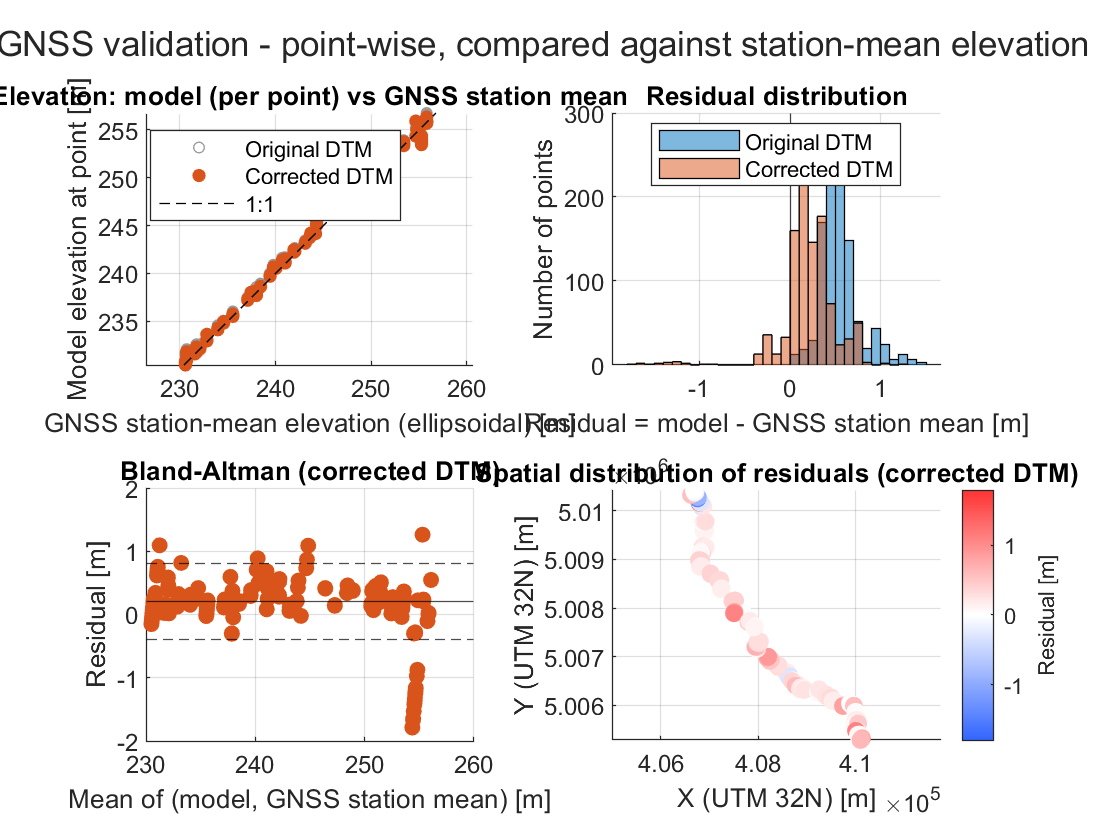

Tstats = 6×8 table
                                           N        ME       Median       SD        RMSE        MAE       NMAD      P95_abs
                                          ____    _______    _______    _______    _______    _______    _______    _______

    Corrected | all                       1002    0.20685     0.2017    0.30971    0.37231    0.28606    0.19893    0.70983
    Original | all                        1002    0.55185     0.5164    0.22326    0.59526    0.55185    0.16433      1.002
    Corrected | inside corrected area      956    0.19593    0.19616     0.3091    0.36583    0.27895    0.18812    0.70973
    Original | inside correct

Tsec = 1002×16 table
     PointName     Station        X             Y         z_gnss_station_mean    z_dtm_orig    z_dtm_corr    res_orig    res_corr    DoD_observed    DoD_modelled    inside_corrected_area    local_std_5x5    N_points_in_station    std_within_station    valid
    ___________    _______    __________    __________    ___________________    __________    __________    ________    ________    ____________    ____________    _____________________    _____________    _____________

%% ============================================================
%% VALIDATION
%% ============================================================
gnss_path = '\\nas-camporeale\home\ELISA\07_03_2025_misure\punti_bat.csv';
out_dir   = '\\nas-camporeale\home\ELISA\BATHIMETRY\0_MODIFICHE\validazione_2025';

[Tstats, Tsec] = validation_gnss_mean(gnss_path, raster_dtm, raster_dtm_corrected, R_dtm, mask_extended, out_dir)

% RMSE/MAE migliorano (il modello corregge bene gli errori grandi e sistematici), 
% ma introduce una dispersione "tipica" propria che il metodo di rettangolarizzazione da solo non spiega.

x0 = 406750; y0 = 5010300;   % approssima dalle coordinate della tabella s006
dmat = sqrt((x_matrix - x0).^2 + (y_matrix - y0).^2);
hit_rows = find(min(dmat, [], 2, 'omitnan') < 60);
T = table(all_centerlines(hit_rows,1), all_centerlines(hit_rows,6), all_centerlines(hit_rows,4), ...
    widths_all(hit_rows), sect_slope(hit_rows), Q_map(hit_rows), h_rect_all(hit_rows), z_rect_all(hit_rows), ...
    'VariableNames', {'ID','tronco','z_coords','width','slope','Q','h_rect','z_rect'});
disp(T)

    ID     tronco    z_coords    width      slope        Q       h_rect     z_rect
    ___    ______    ________    _____    _________    ______    _______    ______

    141      6        255.85     32.5     0.0051955    4.9934    0.19209    255.66
    142      6        255.82       33     0.0051955    4.9934    0.19033    255.63
    143      6        255.78       33     0.0051955    4.9934    0.19033    255.59
    144      6        255.74     31.5     0.0051955    4.9934    0.19572    255.54
    145      6         255.7     23.5     0.0051955    4.9934    0.23334    255.47
    146      6        255.63     11.5     0.0051955    4.9934    0.35827    255.28
    147      6        255.63     11.5     0.0051955    4.9934  